participant_dir = "D:\FRM\meta-mutual-learning\data\v2-p-00-3";
kdf_list.machine_ctrl = strcat(participant_dir, "\ml-ctrl-20230209-163730\TrainingData_20230209-163730_163919.kdf");
kdf_list.machine_exp = strcat(participant_dir, "\ml-treat-20230210-170452\TrainingData_20230210-170452_170815.kdf");
kdf_list.mutual_ctrl = strcat(participant_dir, "\cl-ctrl-20230209-164228\TaskData_20230209-164228.kdf");
kdf_list.mutual_exp = strcat(participant_dir, "\cl-treat-20230210-171300\TaskData_20230210-171300.kdf");
kdf_list.human_ctrl = strcat(participant_dir, "\hl-ctrl-20230209-165513\TaskData_20230209-165513.kdf");
kdf_list.human_exp = strcat(participant_dir, "\hl-treat-20230210-173317\TaskData_20230210-173317.kdf");

participant_dir = "D:\FRM\meta-mutual-learning\data\p-03";
kdf_list.machine_ctrl = strcat(participant_dir, "\ml-ctrl-20230223-172533\TrainingData_20230223-172533_172849.kdf");
kdf_list.machine_exp = strcat(participant_dir, "\ml-treat-20230223-164917\TrainingData_20230223-164917_165203.kdf");
kdf_list.mutual_ctrl = strcat(participant_dir, "\cl-ctrl-20230223-173203\TaskData_20230223-173203.kdf");
kdf_list.mutual_exp = strcat(participant_dir, "\cl-treat-20230223-165643\TaskData_20230223-165643.kdf");
kdf_list.human_ctrl = strcat(participant_dir, "\hl-ctrl-20230223-174547\TaskData_20230223-174547.kdf");
kdf_list.human_exp = strcat(participant_dir, "\hl-treat-20230223-171403\TaskData_20230223-171403.kdf");

p = Participant("Pilot", "Stroke", kdf_list);

Creating new participant: Pilot
	Adding machine learning task
		Adding control experiment
Channel selection
Channel selection
Channel selection
Channel selection
Channel selection
Channel selection
Channel selection
Channel selection
Channel selection
Channel selection
		Adding treatment experiment
Channel selection
Channel selection
Channel selection
Channel selection
Channel selection
Channel selection
Channel selection
Channel selection
Channel selection
Channel selection
	Adding mutual learning task
		Adding control experiment
		Adding treatment experiment
	Adding human learning task
		Adding control experiment
		Adding treatment experiment
Done


## Co-Adaptive Learning Analysis

control_tbl = p.mutual_experiment.control_task.data_tbl;
control_t = control_tbl.Time;
control_des = control_tbl.Targets(:,[1,12]);
control_pred = control_tbl.Kalman(:,[1,12]);

experiment_tbl = p.mutual_experiment.experimental_task.data_tbl;
experiment_t = experiment_tbl.Time;
experiment_des = experiment_tbl.Targets(:,[1,12]);
experiment_pred = experiment_tbl.Kalman(:,[1,12]);

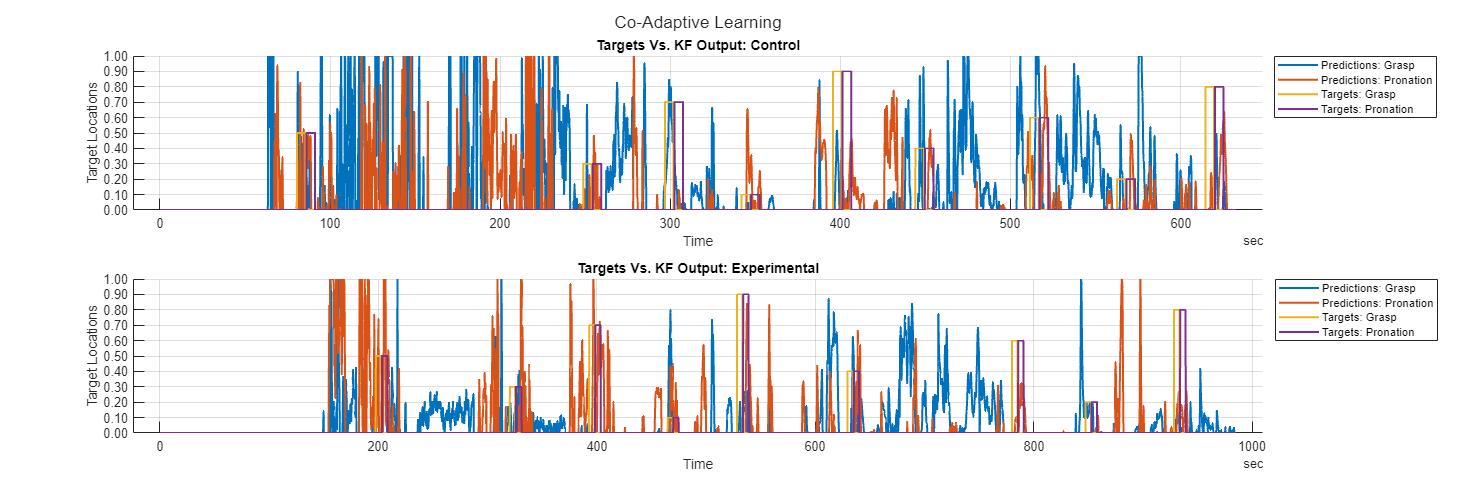

figure('Units','centimeters','Position',[0, 0, 75, 25])
tlo = tiledlayout(2,1);
nexttile
plot(control_t, [control_pred, control_des], LineWidth=1.5)
legend('Predictions: Grasp', 'Predictions: Pronation', 'Targets: Grasp', 'Targets: Pronation', Location='northeastoutside')
title('Targets Vs. KF Output: Control')
xlabel("Time")
ylabel('Target Locations')
ytickformat('%,0.2f')
yticks([0:0.1:1])
box off
grid on

nexttile
plot(experiment_t, [experiment_pred, experiment_des], LineWidth=1.5)
legend('Predictions: Grasp', 'Predictions: Pronation', 'Targets: Grasp', 'Targets: Pronation', Location='northeastoutside')
title('Targets Vs. KF Output: Experimental')
xlabel("Time")
ylabel('Target Locations')
ytickformat('%,0.2f')
yticks([0:0.1:1])
box off
grid on
title(tlo, "Co-Adaptive Learning")

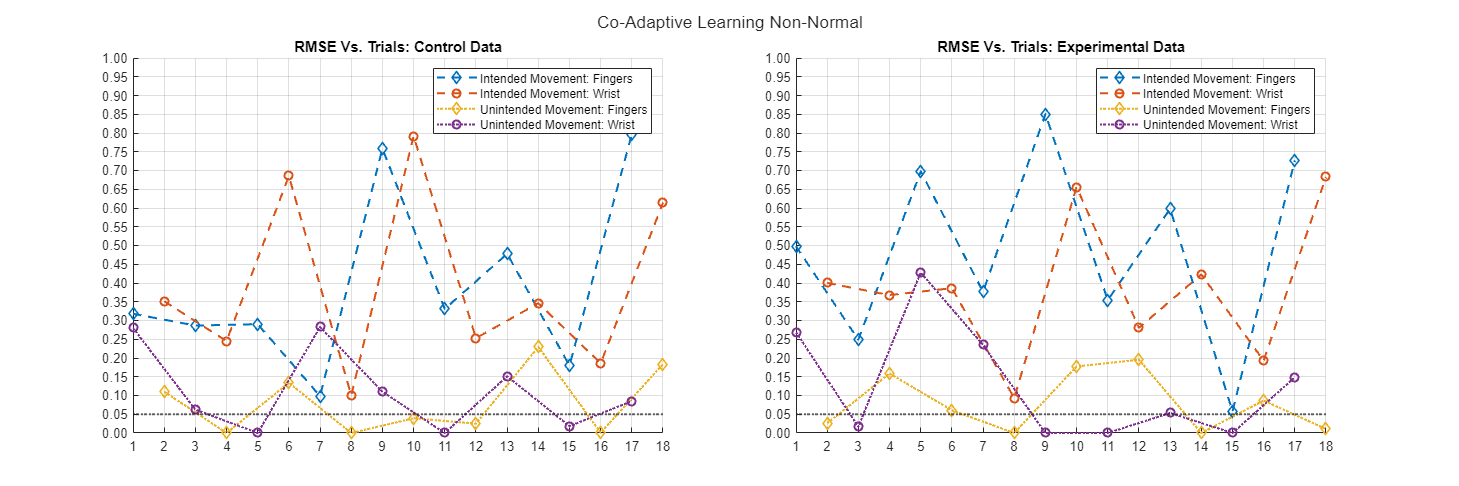

[control_rmse_int, ~] = my_rmse(control_des, control_pred);
[experiment_rmse_int, ~] = my_rmse(experiment_des, experiment_pred);
figure('Units','centimeters','Position', [0, 0, 75, 25])
tlo = plot_rmse_norm(control_rmse_int, experiment_rmse_int, "Co-Adaptive Learning Non-Normal", 1);

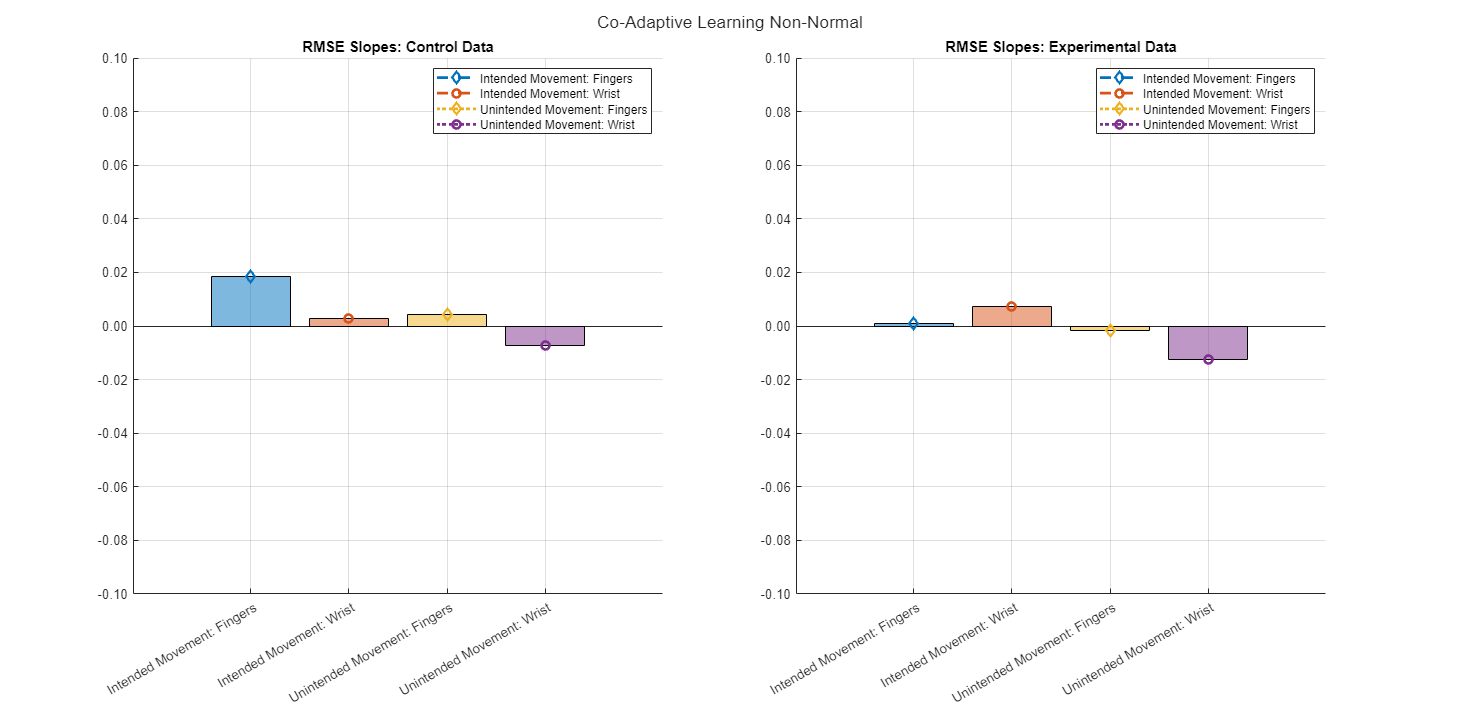

tlo = barplot_rmse_norm(control_rmse_int, experiment_rmse_int, "Co-Adaptive Learning Non-Normal", 1);

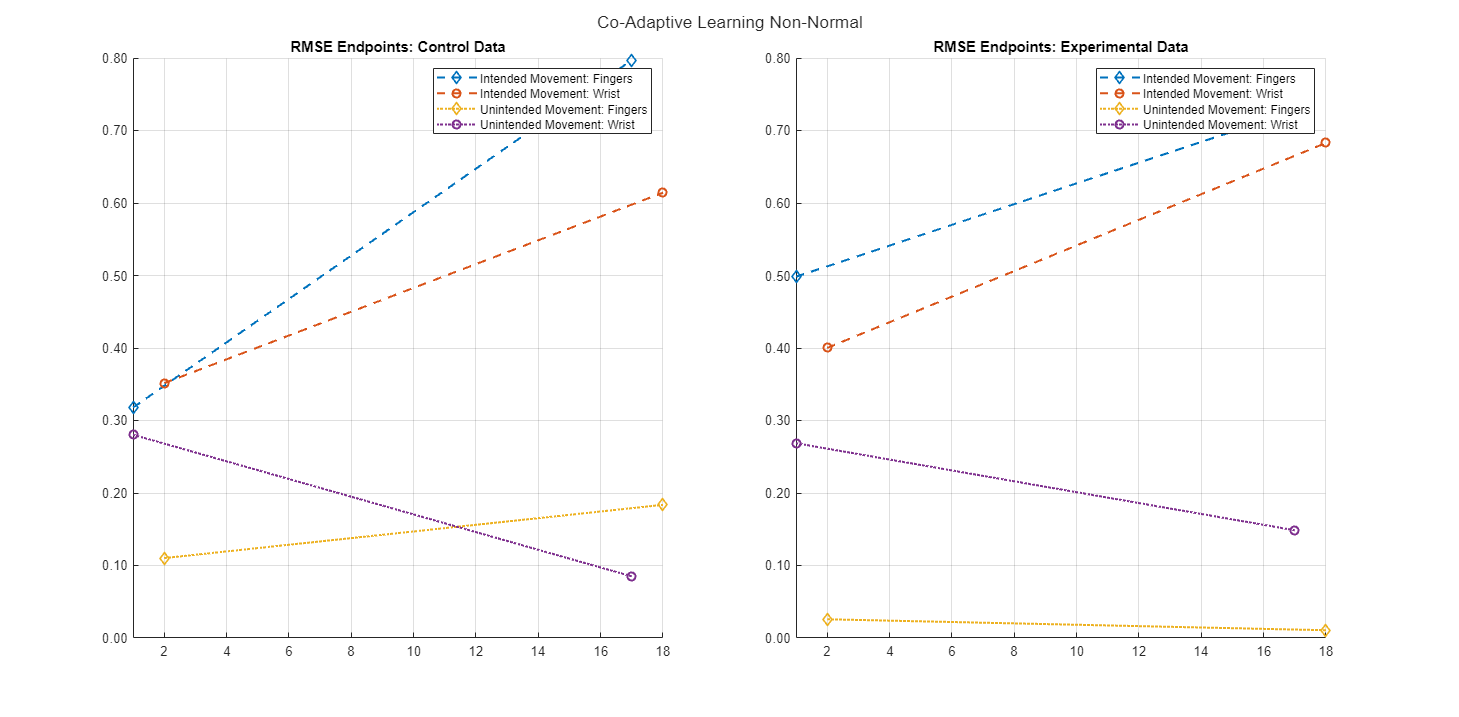

tlo = spaghetti_plot_rmse_norm(control_rmse_int, experiment_rmse_int, "Co-Adaptive Learning Non-Normal", 1);

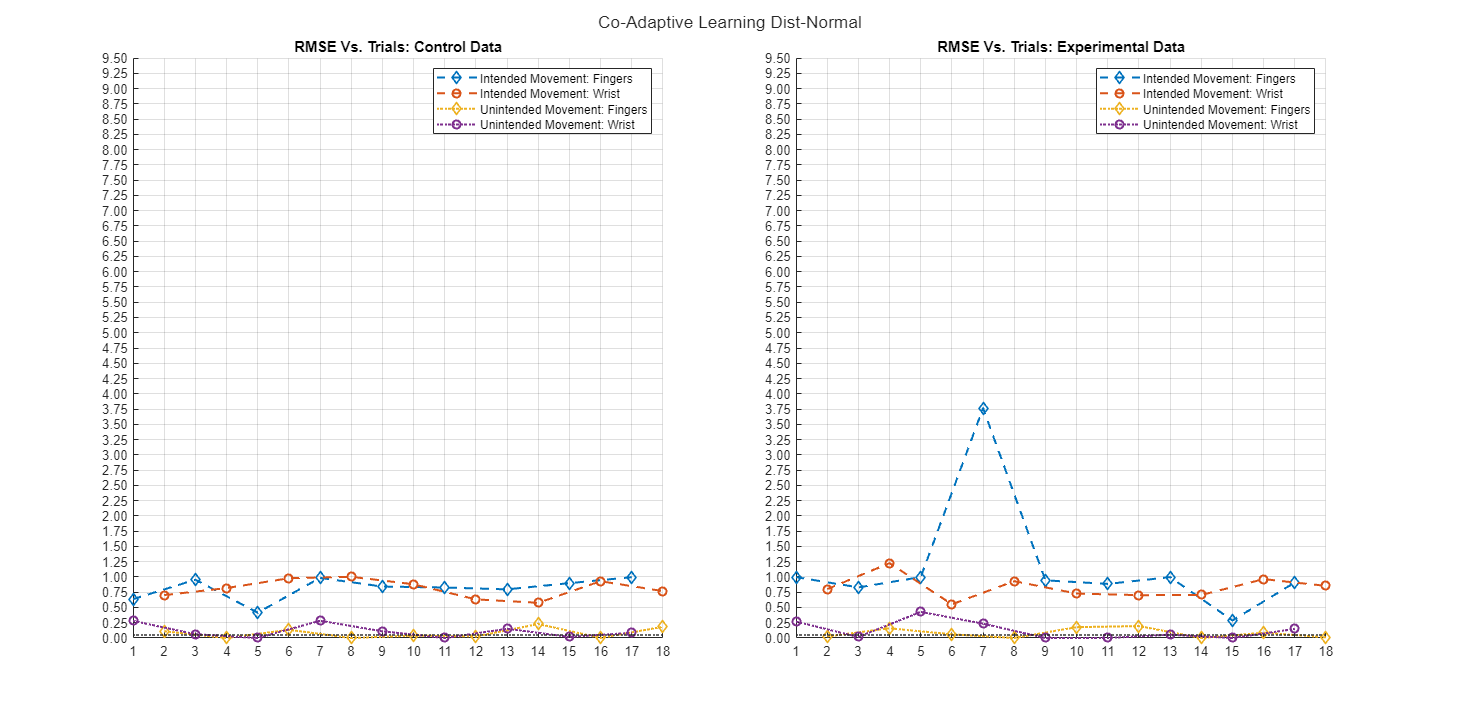

tlo = plot_rmse_norm(control_rmse_int, experiment_rmse_int, "Co-Adaptive Learning Dist-Normal", 2);
ax1 = tlo.Children(2);
ax2 = tlo.Children(4);
ylim(ax1, [0, 9.5])
yticks(ax1, 0:0.25:9.5)
ylim(ax2, [0, 9.5])
yticks(ax2, 0:0.25:9.5)

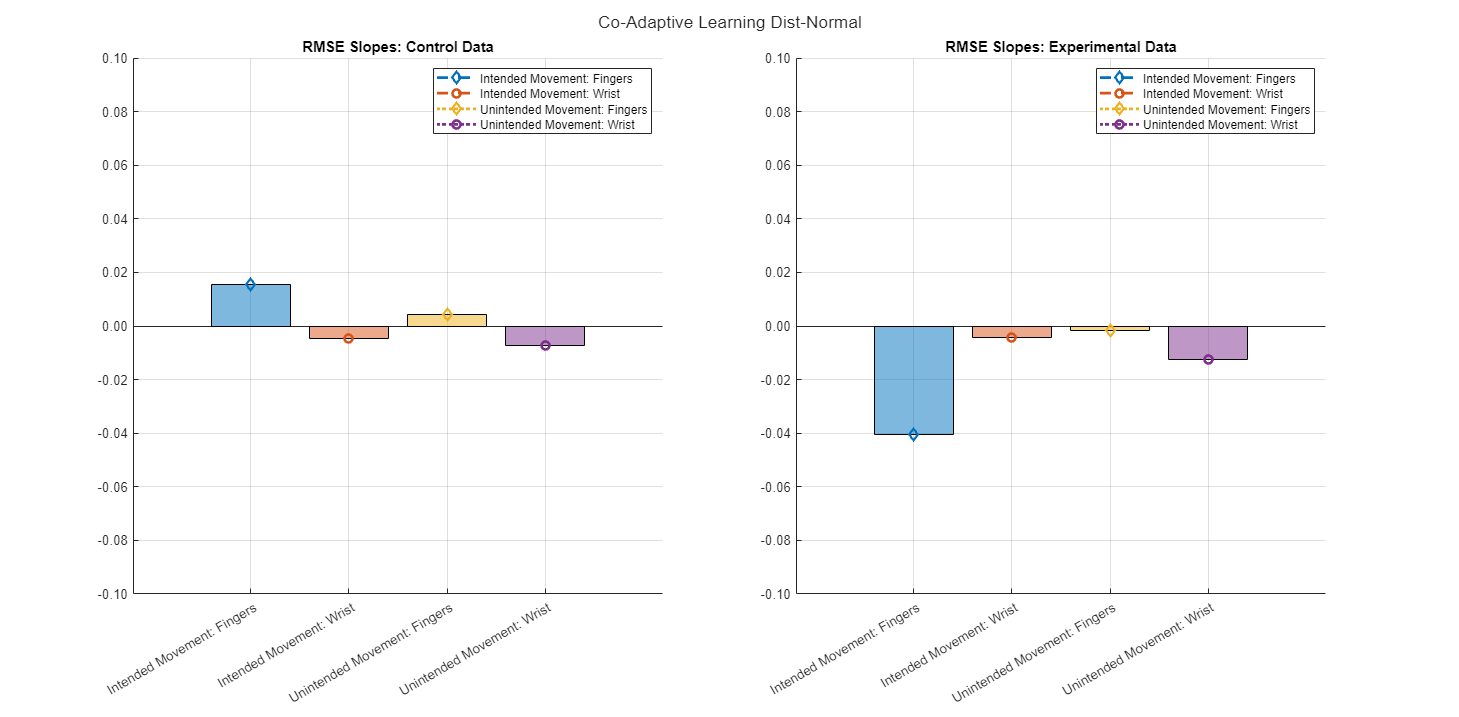

tlo = barplot_rmse_norm(control_rmse_int, experiment_rmse_int, "Co-Adaptive Learning Dist-Normal", 2);

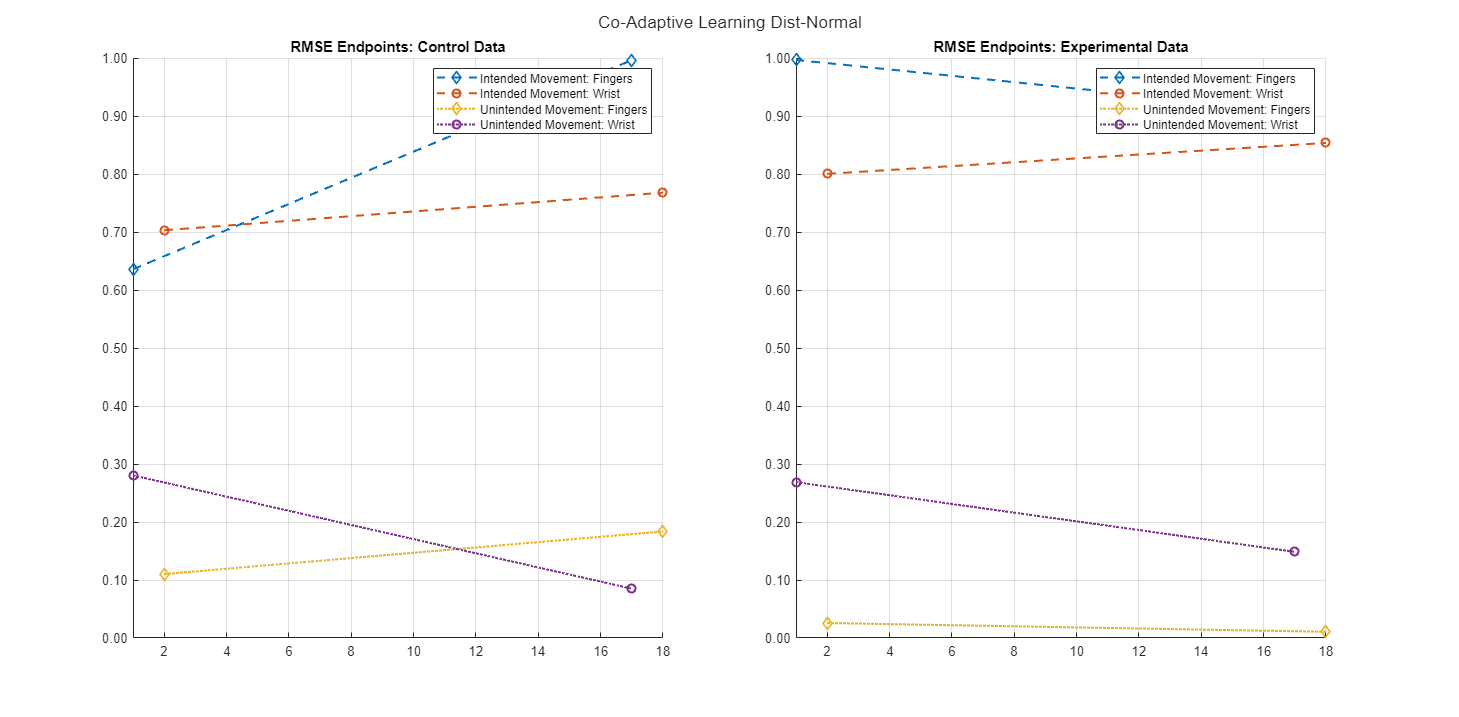

tlo = spaghetti_plot_rmse_norm(control_rmse_int, experiment_rmse_int, "Co-Adaptive Learning Dist-Normal", 2);

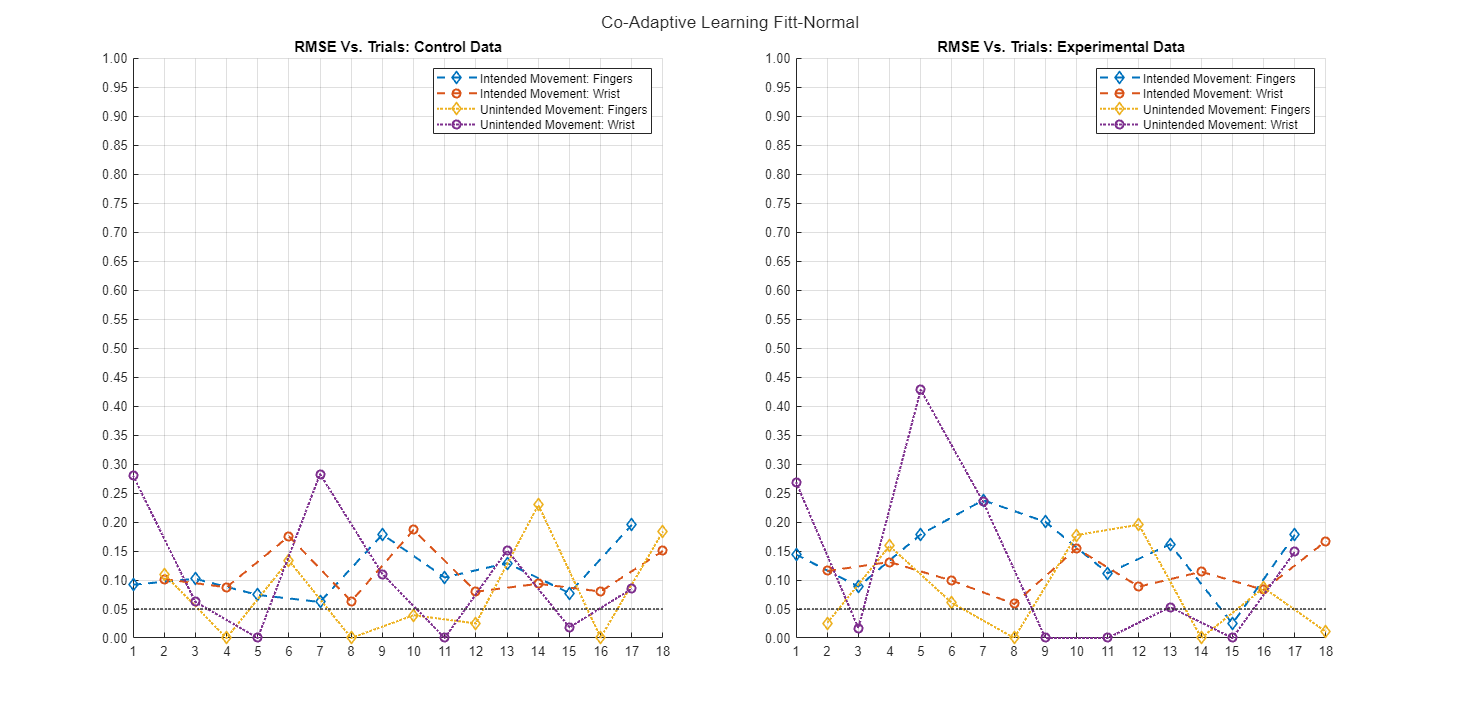

tlo = plot_rmse_norm(control_rmse_int, experiment_rmse_int, "Co-Adaptive Learning Fitt-Normal", 3);

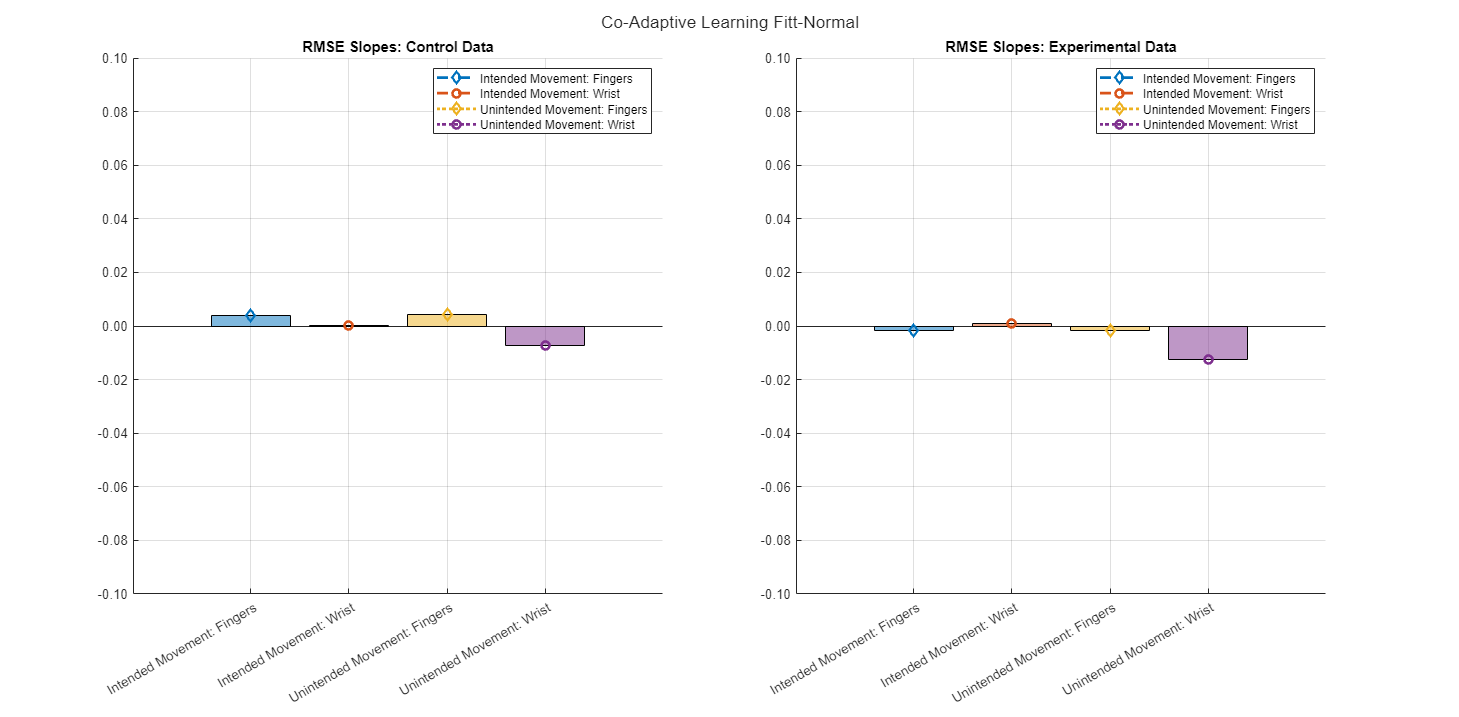

tlo = barplot_rmse_norm(control_rmse_int, experiment_rmse_int, "Co-Adaptive Learning Fitt-Normal", 3);

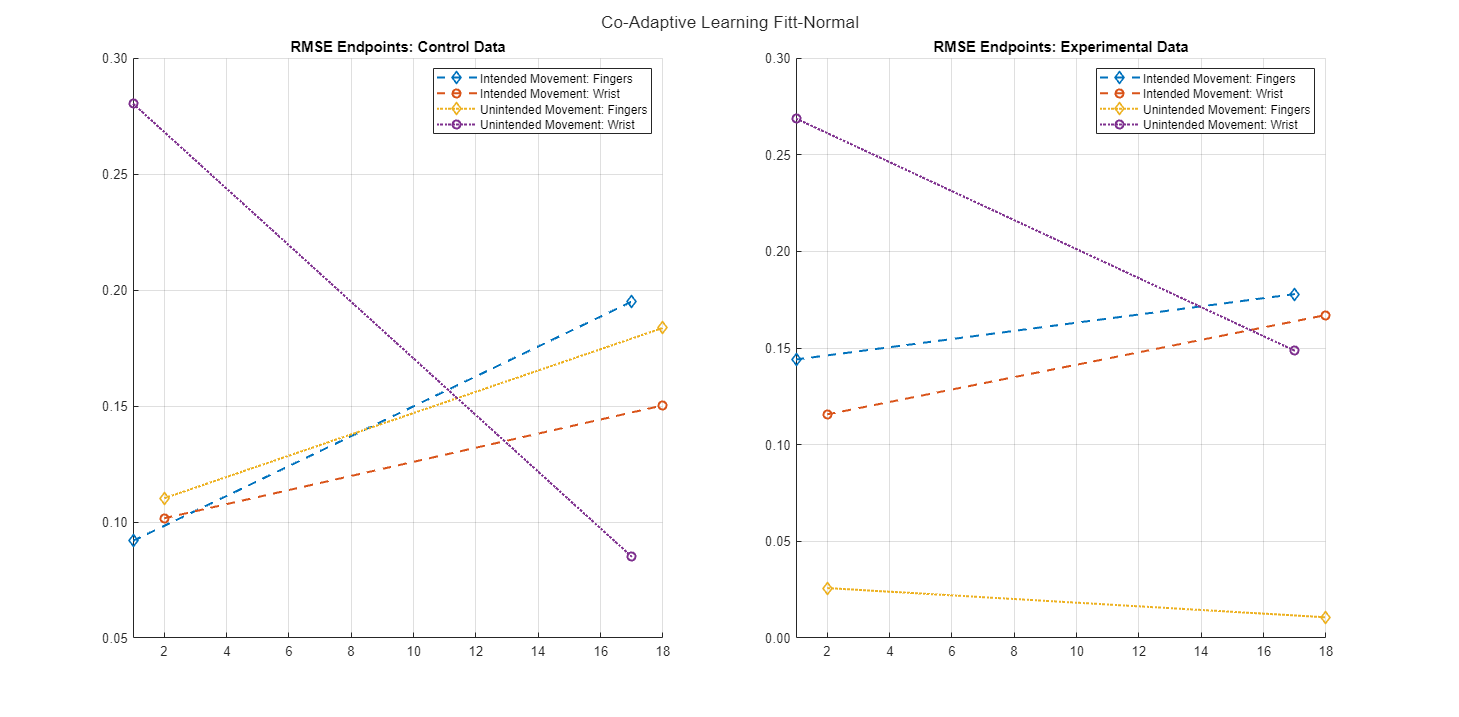

tlo = spaghetti_plot_rmse_norm(control_rmse_int, experiment_rmse_int, "Co-Adaptive Learning Fitt-Normal", 3);

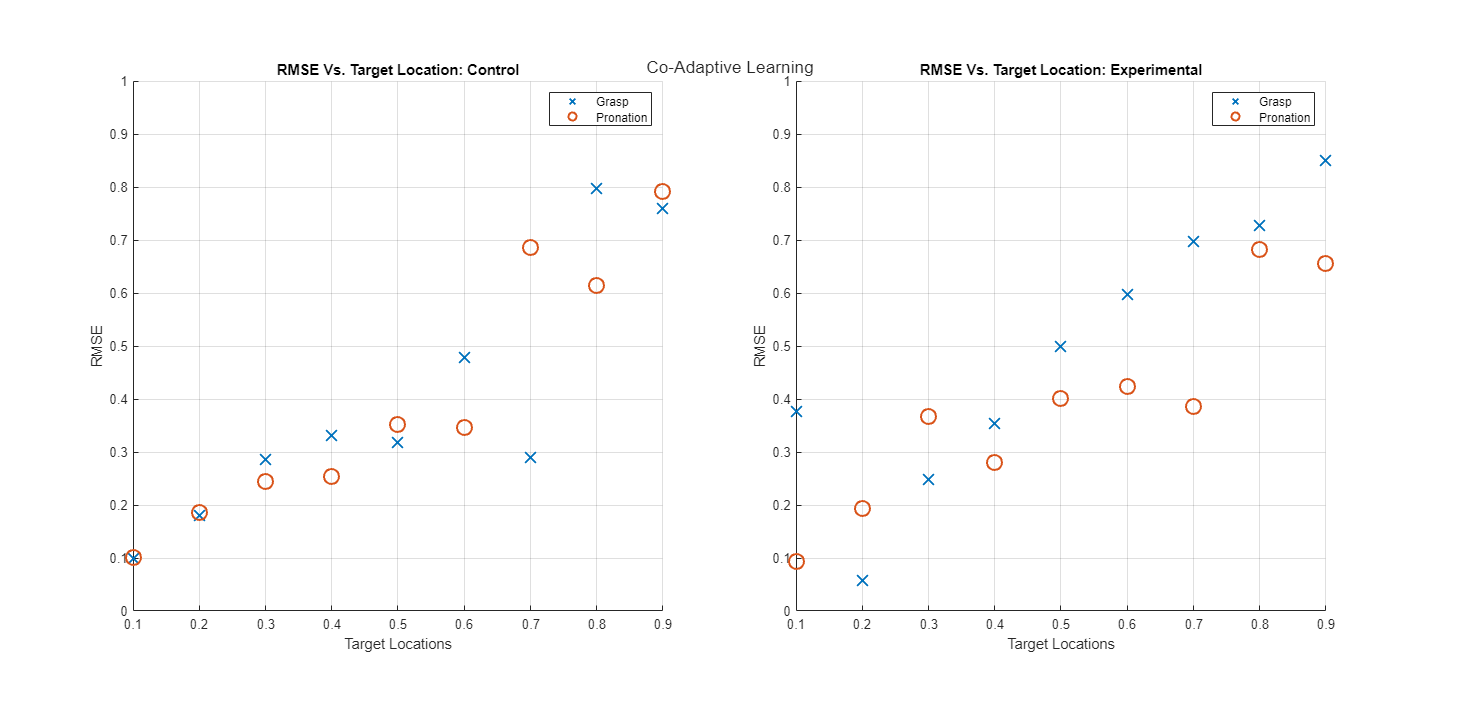

target_vals = repelem([0.5;0.3;0.7;0.1;0.9;0.4;0.6;0.2;0.8], 2);

figure('Units','centimeters','Position',[0, 0, 75, 25])
tlo = tiledlayout(1,2);
nexttile
scatter(target_vals(1:2:end), control_rmse_int(1:2:end,1), 125, 'x', LineWidth=1.5)
hold on
scatter(target_vals(2:2:end), control_rmse_int(2:2:end,1), 125, 'o', LineWidth=1.5)
hold off
xlim([0.1, 0.9])
xticks([0.1:0.1:0.9])
xlabel('Target Locations')
ylim([0, 1])
ylabel('RMSE')
grid on
title('RMSE Vs. Target Location: Control')
legend('Grasp', 'Pronation')
axis square

nexttile
scatter(target_vals(1:2:end), experiment_rmse_int(1:2:end,1), 125, 'x', LineWidth=1.5)
hold on
scatter(target_vals(2:2:end), experiment_rmse_int(2:2:end,1), 125, 'o', LineWidth=1.5)
hold off
xlim([0.1, 0.9])
xticks([0.1:0.1:0.9])
xlabel('Target Locations')
ylim([0, 1])
ylabel('RMSE')
grid on
title('RMSE Vs. Target Location: Experimental')
legend('Grasp', 'Pronation')
axis square

title(tlo, 'Co-Adaptive Learning')

## Human Learning Analysis

control_tbl = p.human_experiment.control_task.data_tbl;
control_t = control_tbl.Time;
control_des = control_tbl.Targets(:,[1,12]);
control_pred = control_tbl.Kalman(:,[1,12]);

experiment_tbl = p.human_experiment.experimental_task.data_tbl;
experiment_t = experiment_tbl.Time;
experiment_des = experiment_tbl.Targets(:,[1,12]);
experiment_pred = experiment_tbl.Kalman(:,[1,12]);

### Data Viz

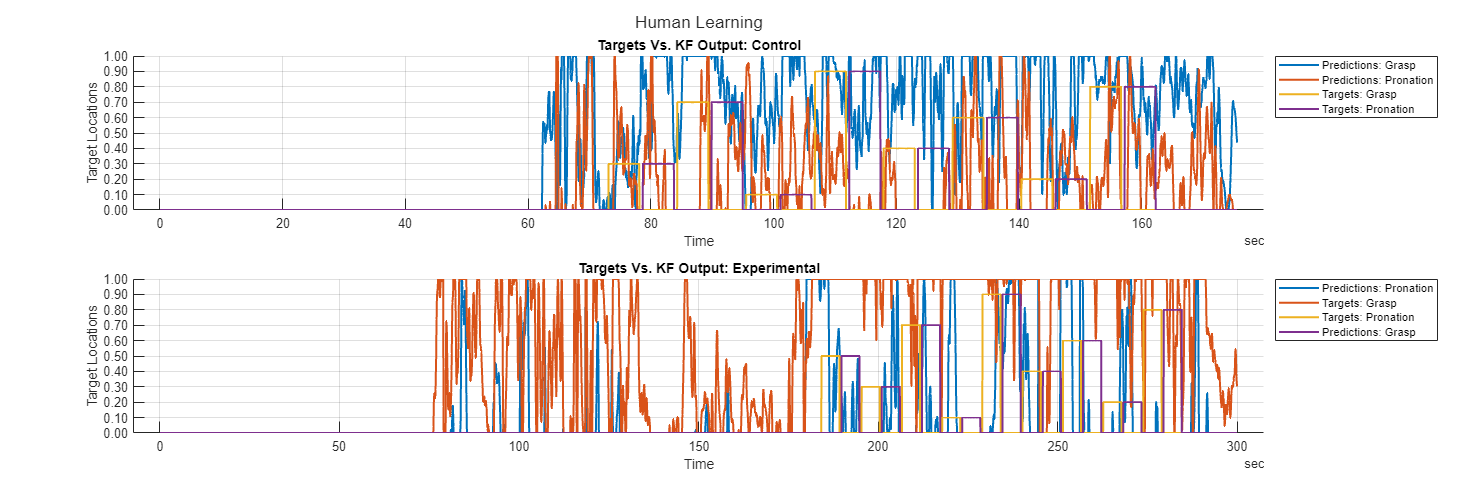

figure('Units','centimeters','Position',[0, 0, 75, 25])
tlo = tiledlayout(2,1);
nexttile
plot(control_t, [control_pred, control_des], LineWidth=1.5)
legend('Predictions: Grasp', 'Predictions: Pronation', 'Targets: Grasp', 'Targets: Pronation', Location='northeastoutside')
title('Targets Vs. KF Output: Control')
xlabel("Time")
ylabel('Target Locations')
ytickformat('%,0.2f')
yticks([0:0.1:1])
box off
grid on

nexttile
plot(experiment_t, [experiment_pred, experiment_des], LineWidth=1.5)
legend('Predictions: Pronation', 'Targets: Grasp', 'Targets: Pronation', 'Predictions: Grasp', Location='northeastoutside')
title('Targets Vs. KF Output: Experimental')
xlabel("Time")
ylabel('Target Locations')
ytickformat('%,0.2f')
yticks([0:0.1:1])
box off
grid on
title(tlo, "Human Learning")

### RMSE

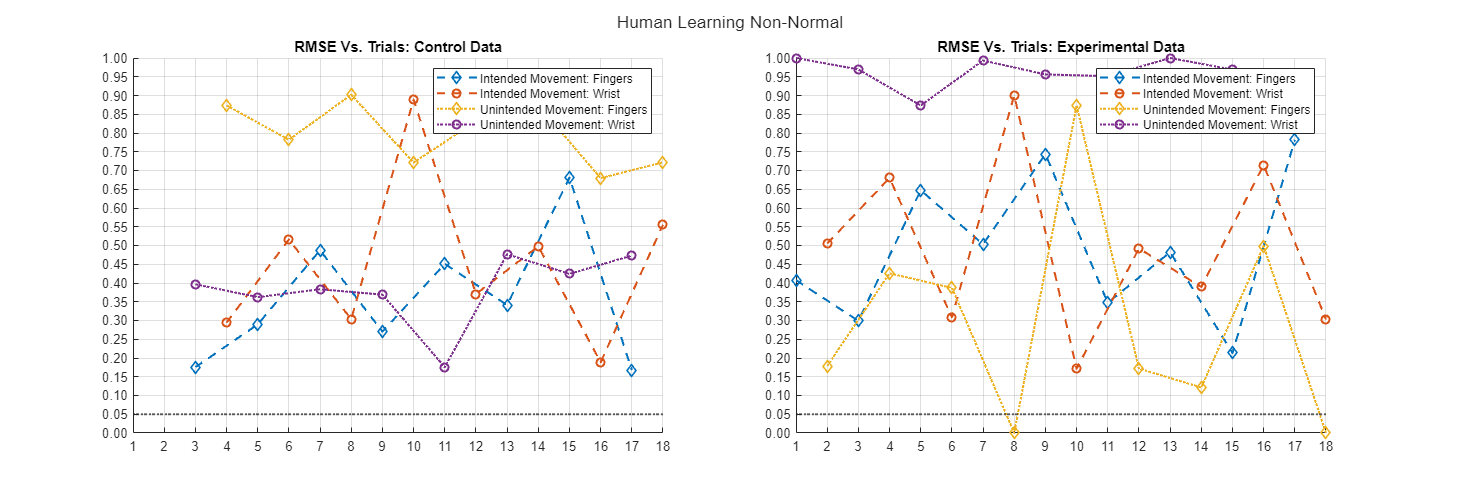

[control_rmse_int, ~] = my_rmse(control_des, control_pred);
[experiment_rmse_int, ~] = my_rmse(experiment_des, experiment_pred);

figure('Units','centimeters','Position',[0, 0, 75, 25])
tlo = plot_rmse_norm([ NaN,NaN; NaN,NaN; control_rmse_int], experiment_rmse_int, "Human Learning Non-Normal", 1);

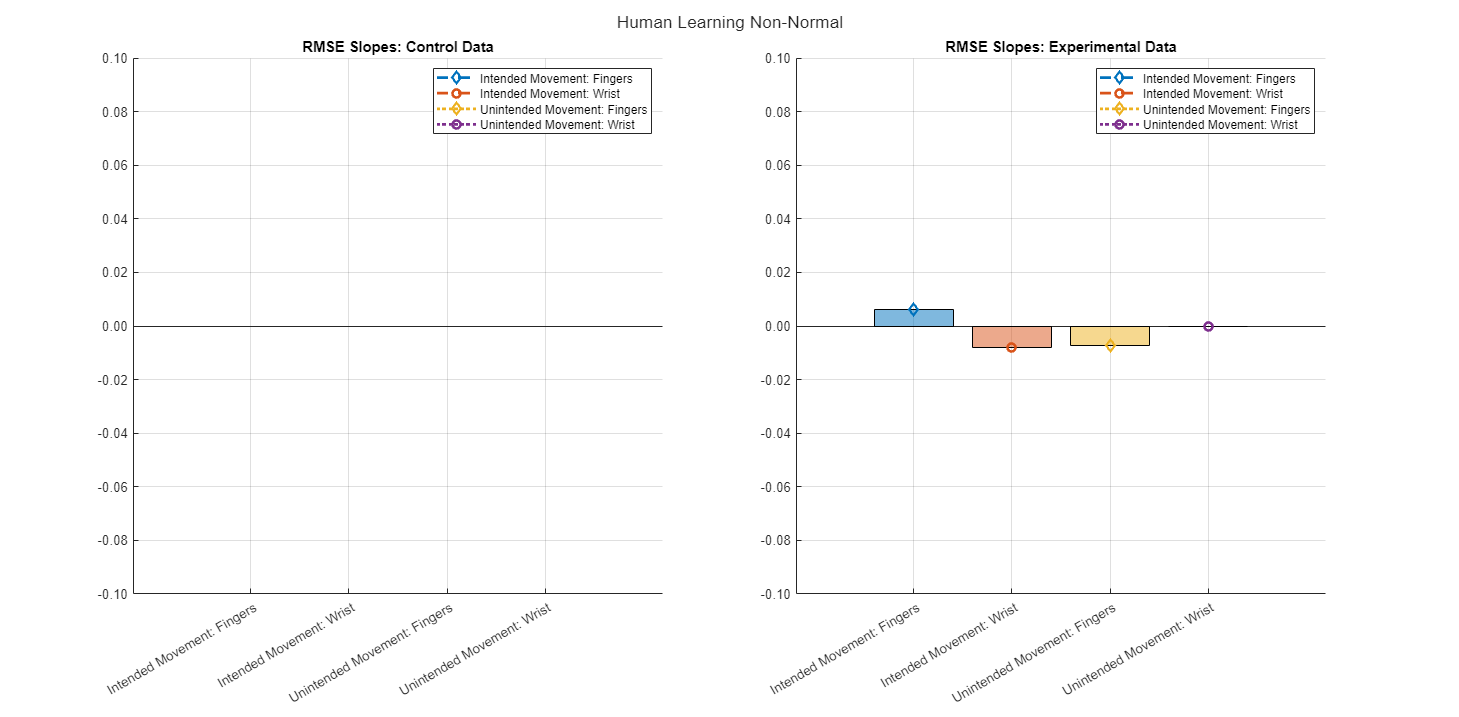

tlo = barplot_rmse_norm([ NaN,NaN; NaN,NaN; control_rmse_int], experiment_rmse_int, "Human Learning Non-Normal", 1);

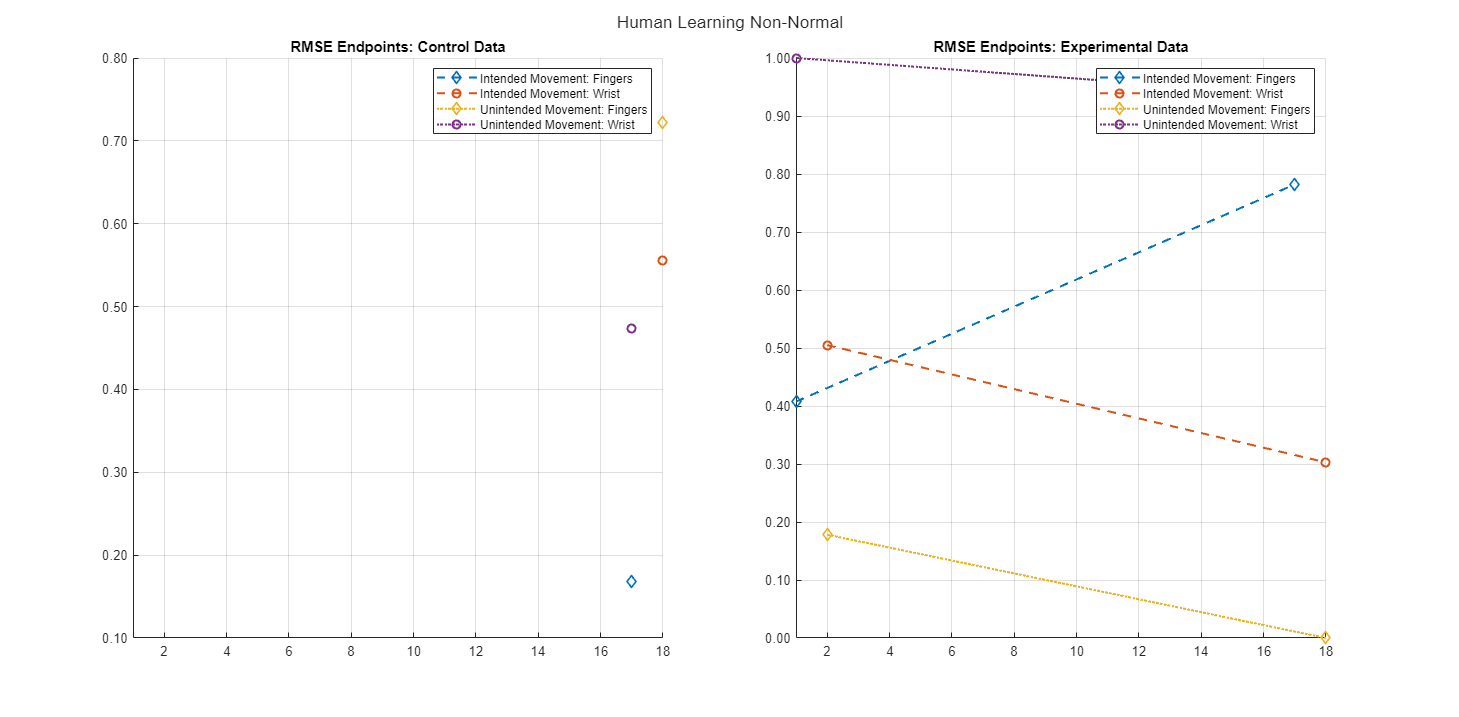

tlo = spaghetti_plot_rmse_norm([ NaN,NaN; NaN,NaN; control_rmse_int], experiment_rmse_int, "Human Learning Non-Normal", 1);

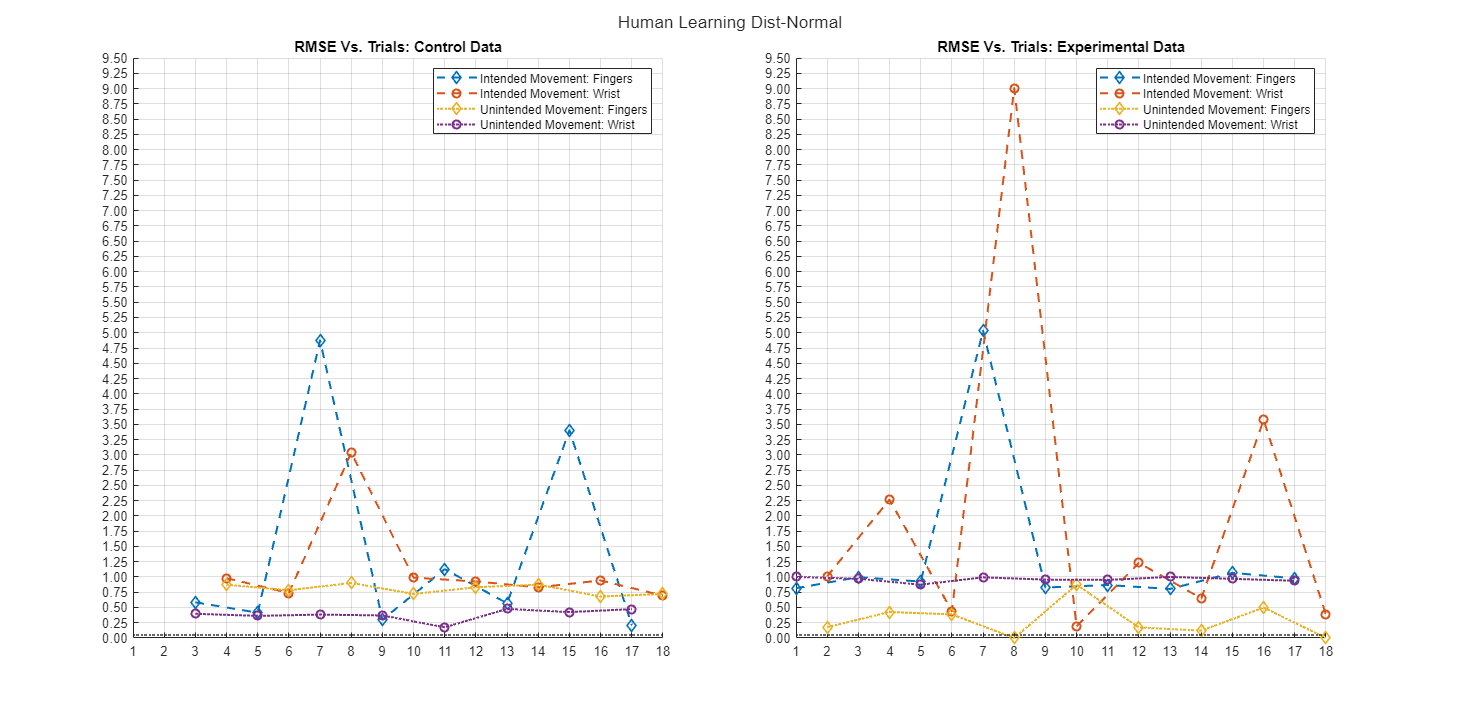


tlo = plot_rmse_norm([ NaN,NaN; NaN,NaN; control_rmse_int], experiment_rmse_int, "Human Learning Dist-Normal", 2);
ax1 = tlo.Children(2);
ax2 = tlo.Children(4);
ylim(ax1, [0, 9.5])
yticks(ax1, 0:0.25:9.5)
ylim(ax2, [0, 9.5])
yticks(ax2, 0:0.25:9.5)

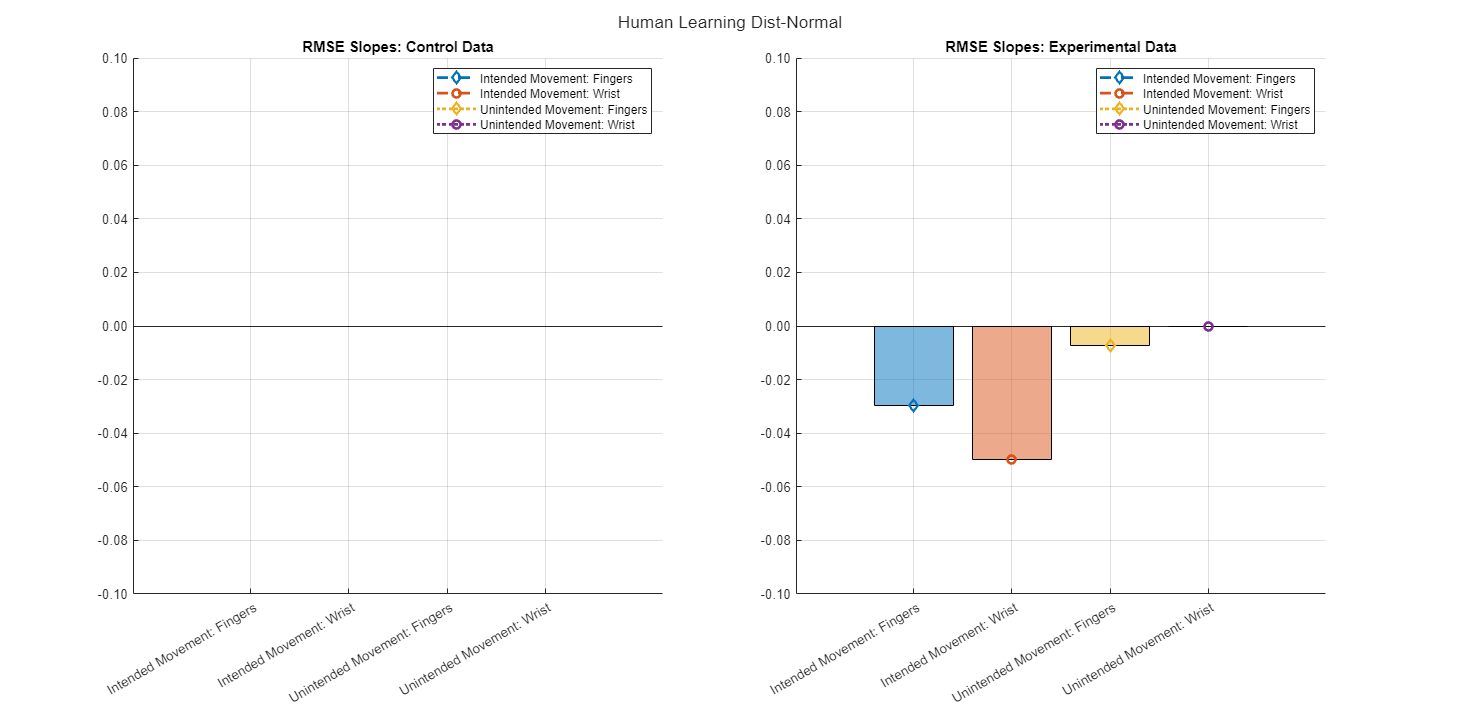

tlo = barplot_rmse_norm([ NaN,NaN; NaN,NaN; control_rmse_int], experiment_rmse_int, "Human Learning Dist-Normal", 2);

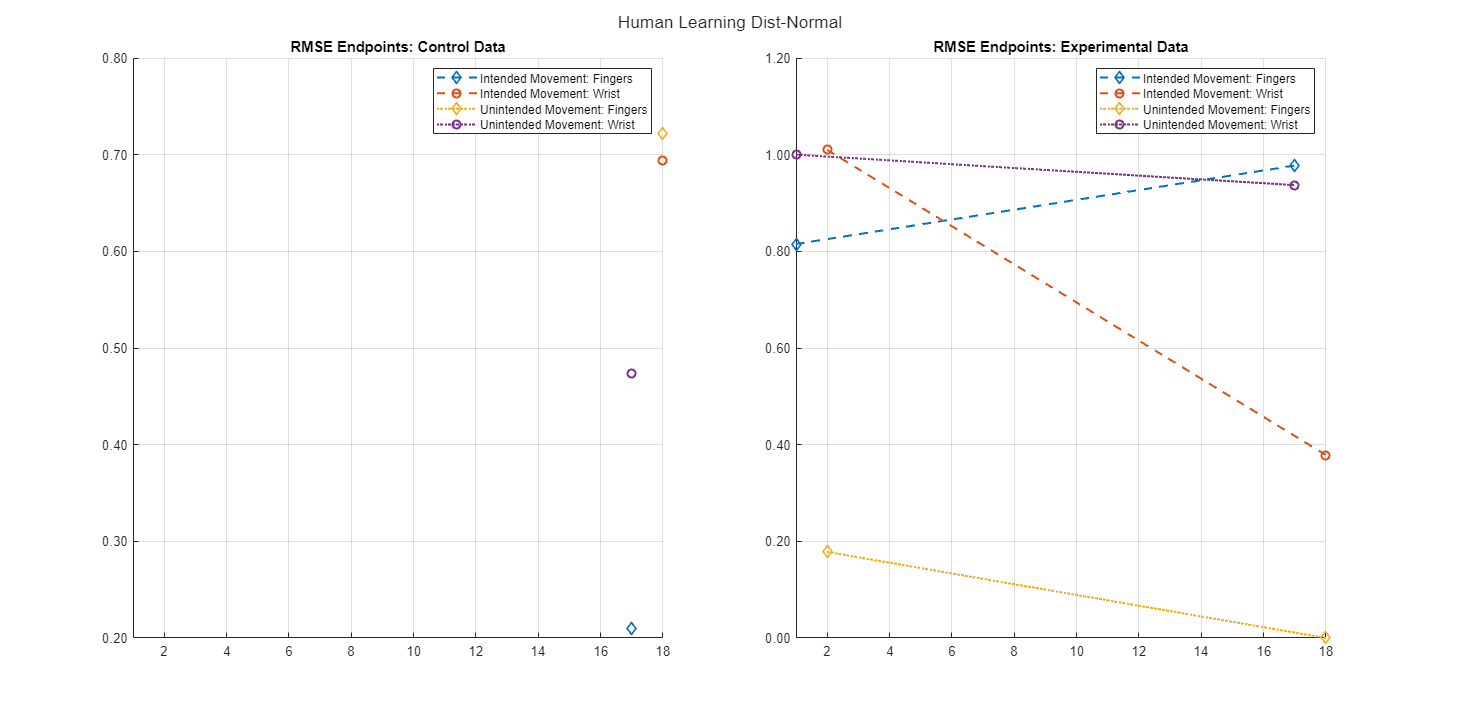

tlo = spaghetti_plot_rmse_norm([ NaN,NaN; NaN,NaN; control_rmse_int], experiment_rmse_int, "Human Learning Dist-Normal", 2);

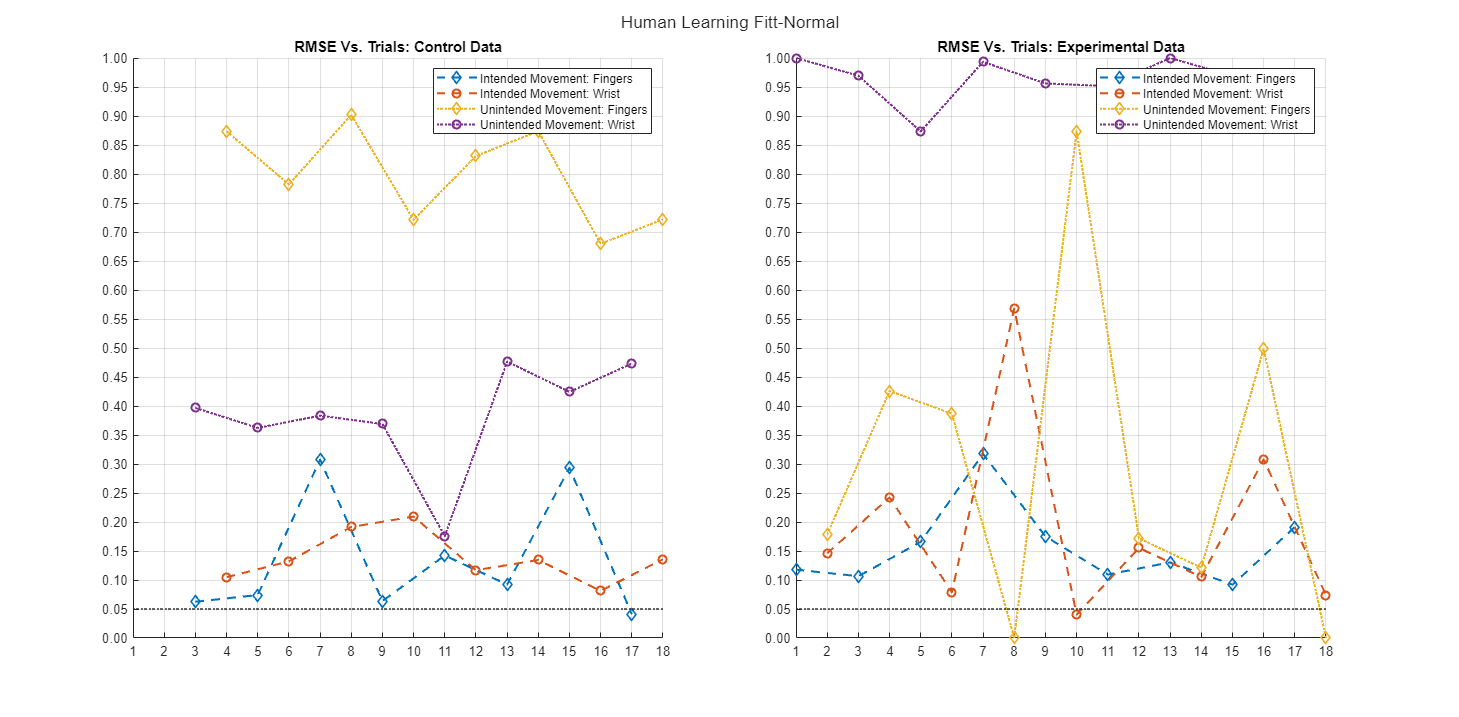


tlo = plot_rmse_norm([ NaN,NaN; NaN,NaN; control_rmse_int], experiment_rmse_int, "Human Learning Fitt-Normal", 3);

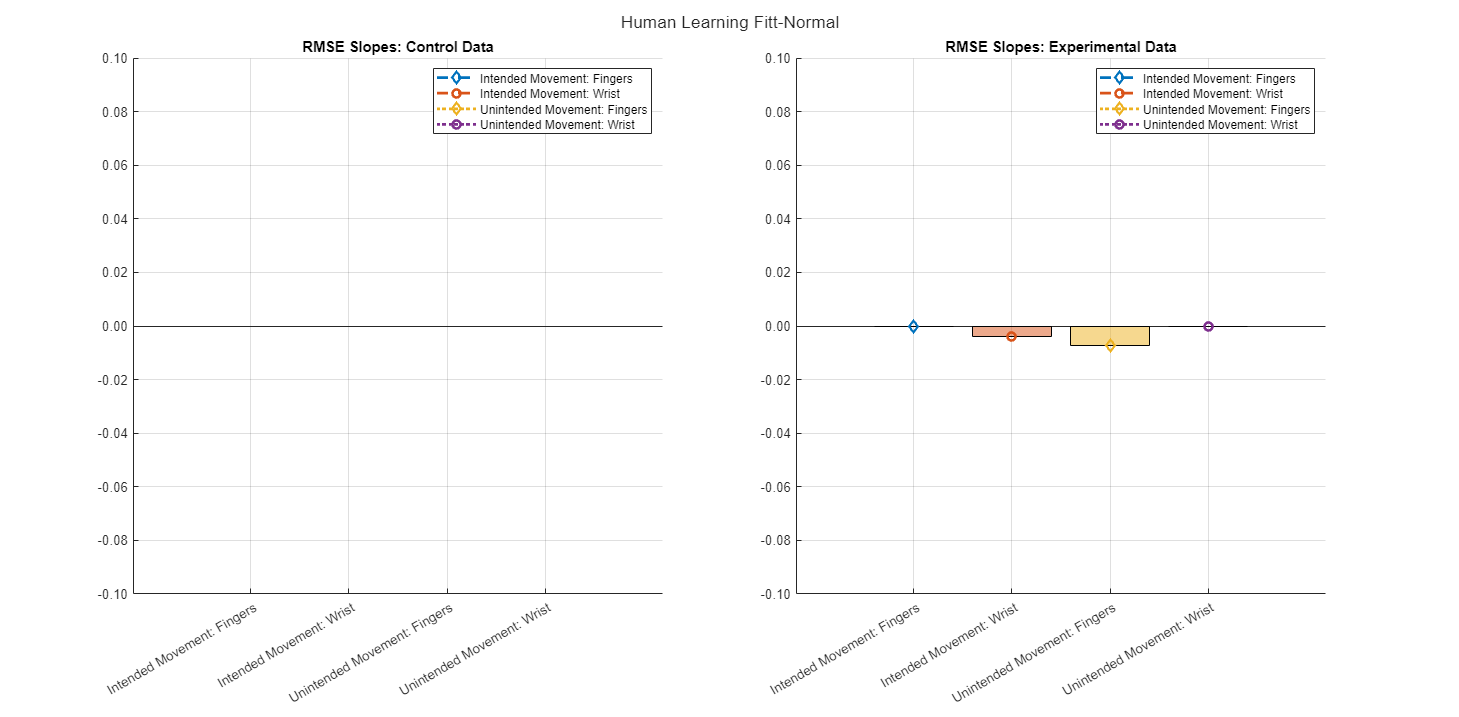

tlo = barplot_rmse_norm([ NaN,NaN; NaN,NaN; control_rmse_int], experiment_rmse_int, "Human Learning Fitt-Normal", 3);

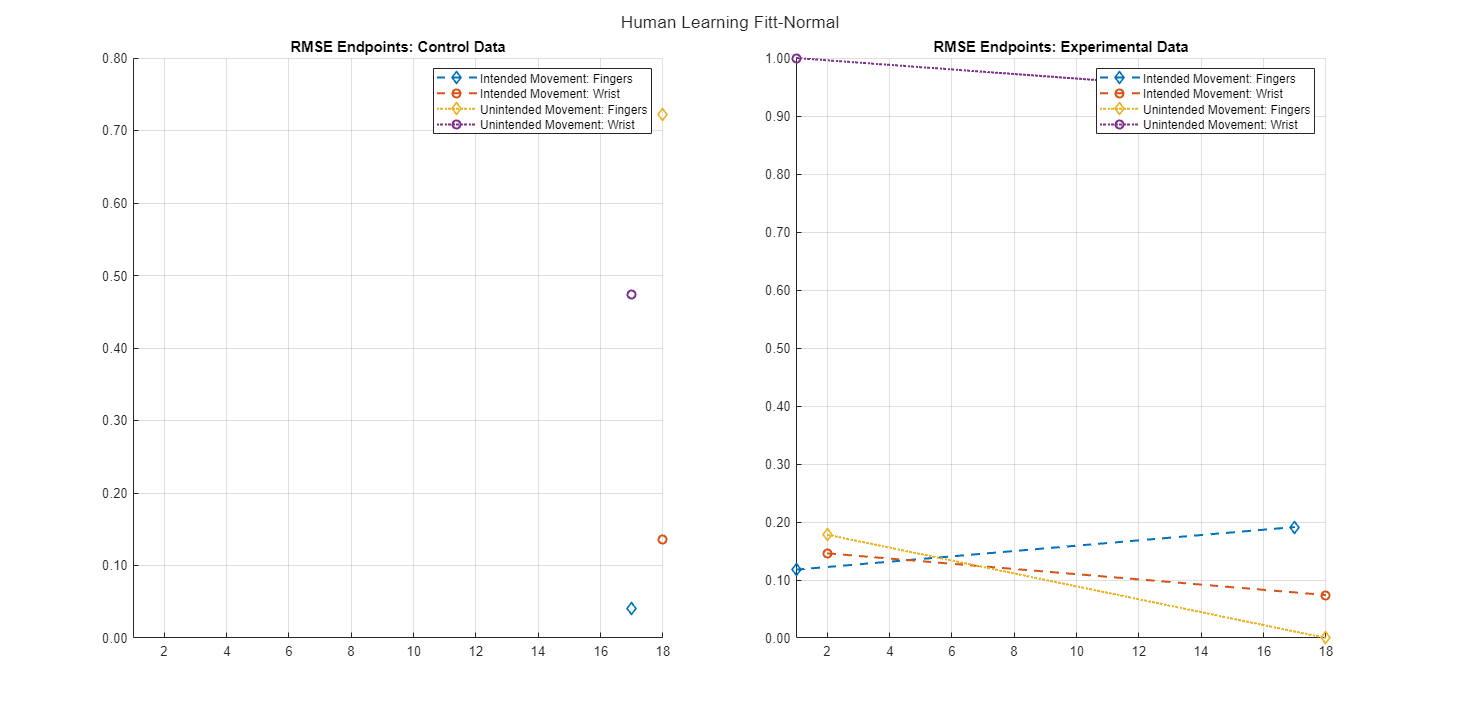

tlo = spaghetti_plot_rmse_norm([ NaN,NaN; NaN,NaN; control_rmse_int], experiment_rmse_int, "Human Learning Fitt-Normal", 3);

### RMSE Distribution

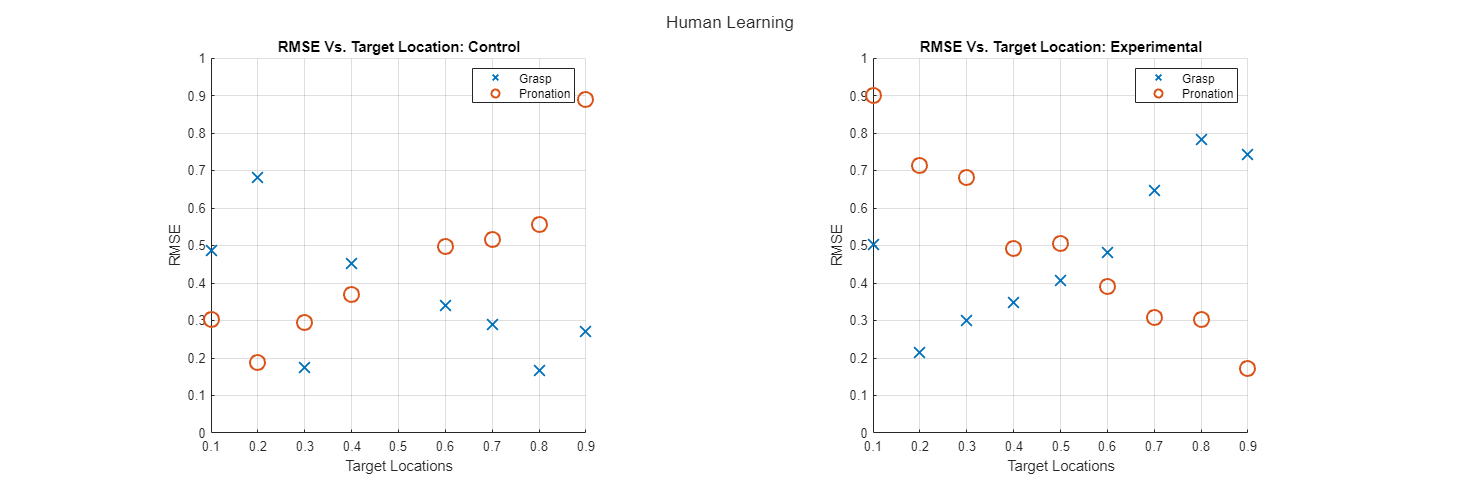

figure('Units','centimeters','Position',[0, 0, 75, 25])
tlo = tiledlayout(1,2);
nexttile
scatter(target_vals(1:2:end), [NaN; control_rmse_int(1:2:end,1)], 125, 'x', LineWidth=1.5)
hold on
scatter(target_vals(2:2:end), [NaN; control_rmse_int(2:2:end,1)], 125, 'o', LineWidth=1.5)
hold off
xlim([0.1, 0.9])
xticks([0.1:0.1:0.9])
xlabel('Target Locations')
ylim([0, 1])
ylabel('RMSE')
grid on
title('RMSE Vs. Target Location: Control')
legend('Grasp', 'Pronation')
axis square

nexttile
scatter(target_vals(1:2:end), experiment_rmse_int(1:2:end,1), 125, 'x', LineWidth=1.5)
hold on
scatter(target_vals(2:2:end), experiment_rmse_int(2:2:end,1), 125, 'o', LineWidth=1.5)
hold off
xlim([0.1, 0.9])
xticks([0.1:0.1:0.9])
xlabel('Target Locations')
ylim([0, 1])
ylabel('RMSE')
grid on
title('RMSE Vs. Target Location: Experimental')
legend('Grasp', 'Pronation')
axis square

title(tlo, 'Human Learning')

## Machine Learning Analysis

control_tbl = p.machine_experiment.control_task.data_tbl;
control_t = control_tbl.Time;
control_des = control_tbl.Targets(:,[1,12]);

experiment_tbl = p.machine_experiment.experimental_task.data_tbl;
experiment_t = experiment_tbl.Time;
experiment_des = experiment_tbl.Targets(:,[1,12]);
experiment_pred = experiment_tbl.Kalman_02(:,[1,12]);

num_filters = 4:width(control_tbl)-1;

for i = 1:length(num_filters)
kf_pred = control_tbl(:,num_filters(i)).Variables;
control_pred = kf_pred(:,[1,12]);
[control_rmse_int, ~] = my_rmse(control_des, control_pred);
if i ==1
    knit_rmse = control_rmse_int(2*i+1:2*i+2,:);
elseif i < length(num_filters)
    knit_rmse = [knit_rmse; control_rmse_int(2*i+1:2*i+2,:)];
end
% disp(num_filters(i))
end
control_rmse_knit = knit_rmse;
num_filters = 4:width(experiment_tbl)-1;

for i = 1:length(num_filters)
kf_pred = experiment_tbl(:,num_filters(i)).Variables;
experiment_pred = kf_pred(:,[1,12]);
[experiment_rmse_int, ~] = my_rmse(experiment_des, experiment_pred);
if i ==1
    knit_rmse = experiment_rmse_int(2*i+1:2*i+2,:);
elseif i < length(num_filters)
    knit_rmse = [knit_rmse; experiment_rmse_int(2*i+1:2*i+2,:)];
end
% disp(num_filters(i))
end
experiment_rmse_knit = knit_rmse;

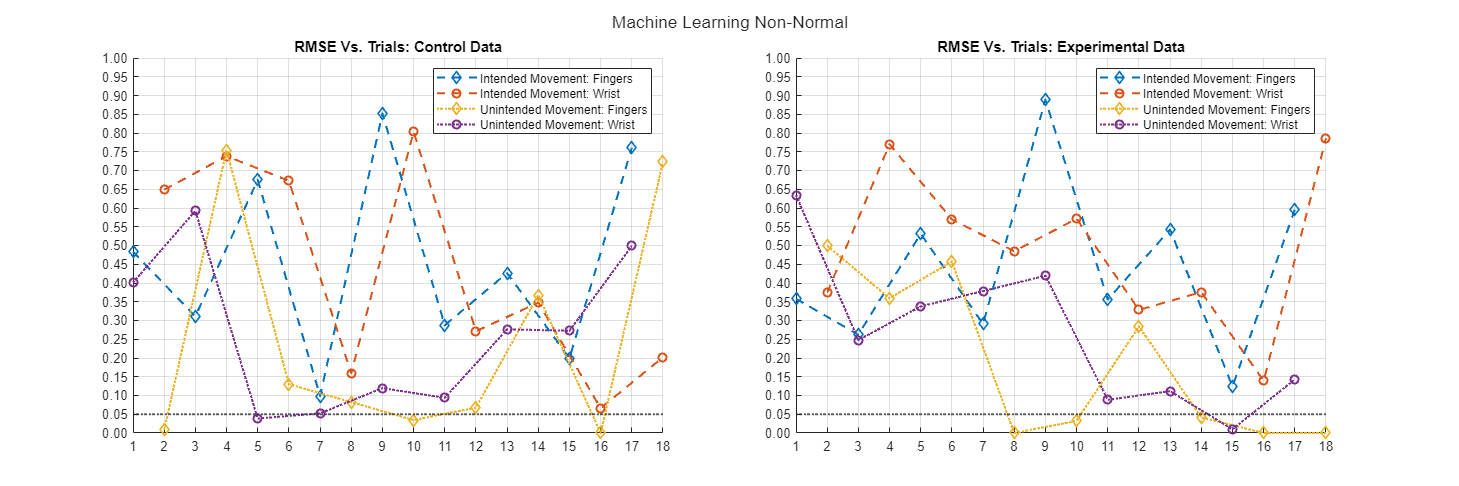

figure('Units','centimeters','Position',[0, 0, 75, 25])
tlo = plot_rmse_norm(control_rmse_knit, experiment_rmse_knit, "Machine Learning Non-Normal", 1);

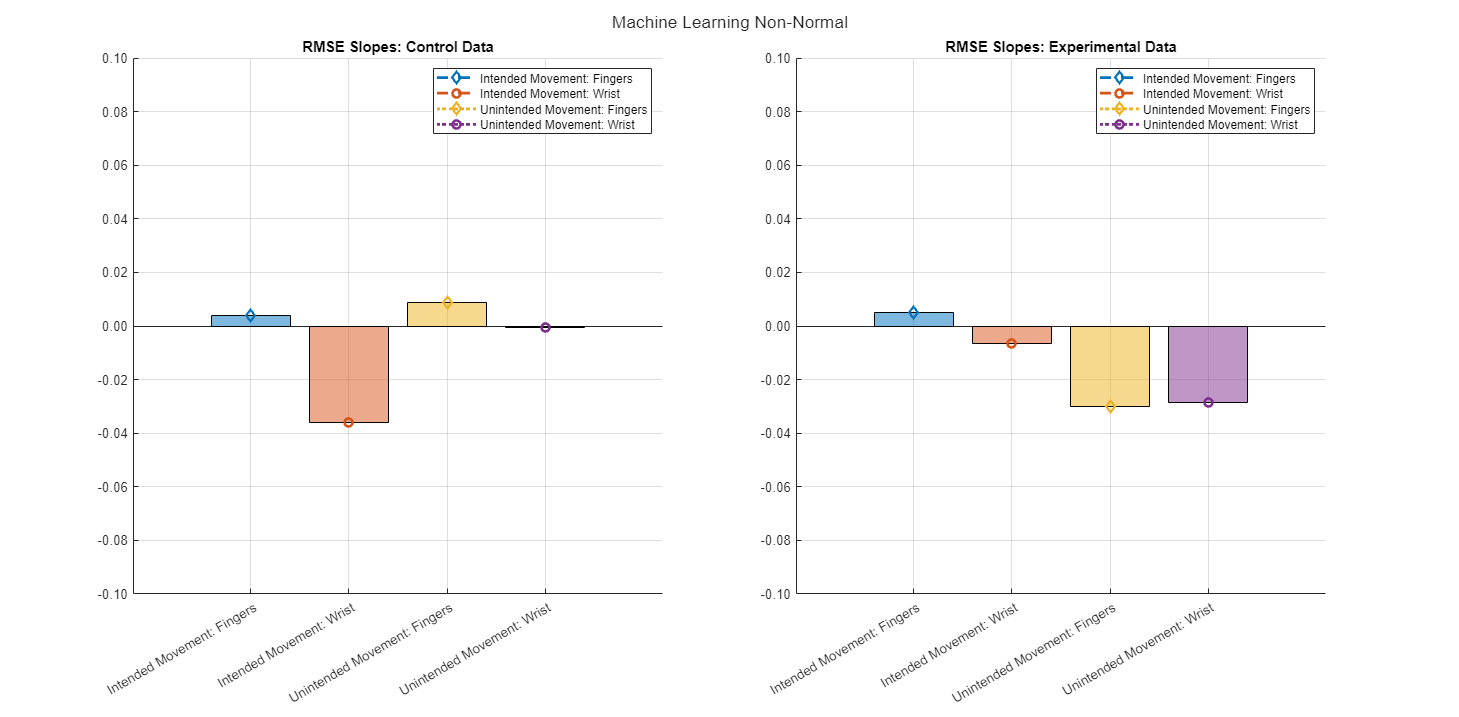

tlo = barplot_rmse_norm(control_rmse_knit, experiment_rmse_knit, "Machine Learning Non-Normal", 1);

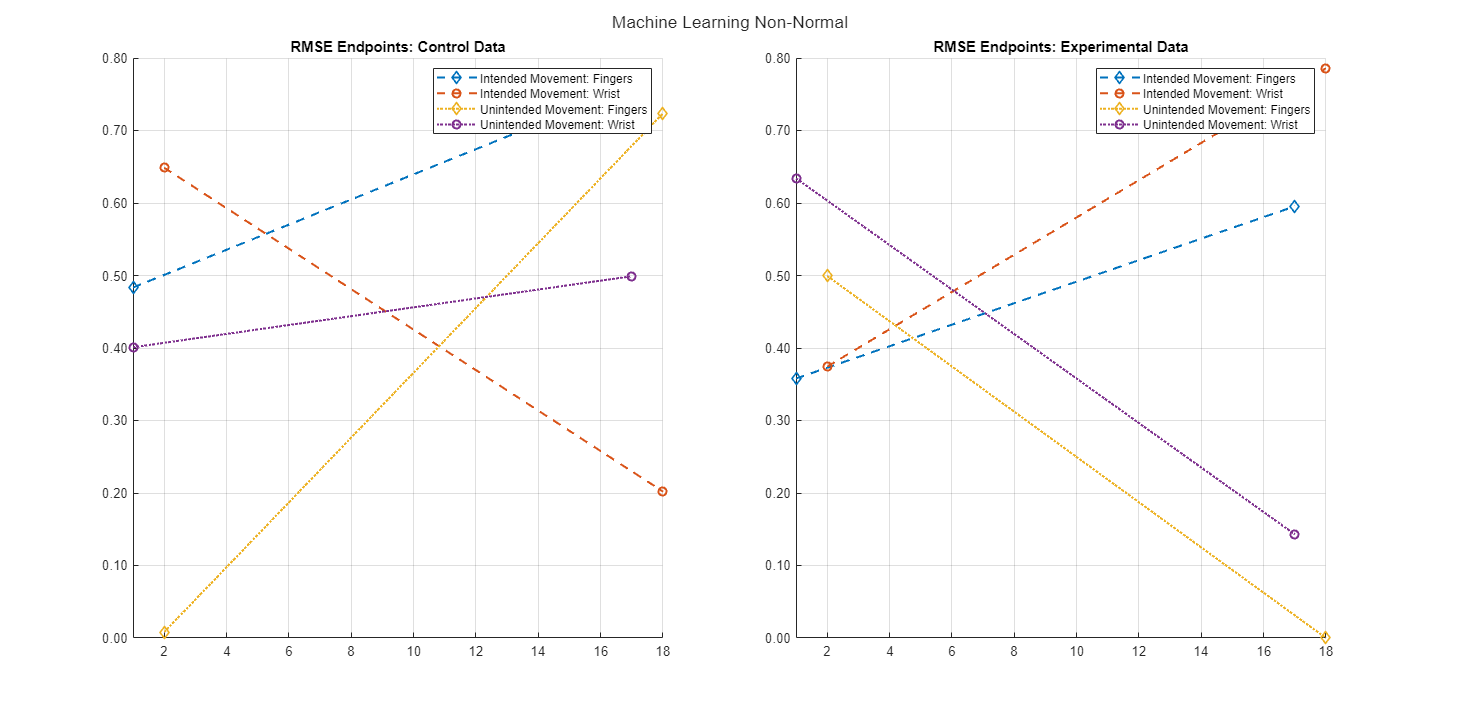

tlo = spaghetti_plot_rmse_norm(control_rmse_knit, experiment_rmse_knit, "Machine Learning Non-Normal", 1);

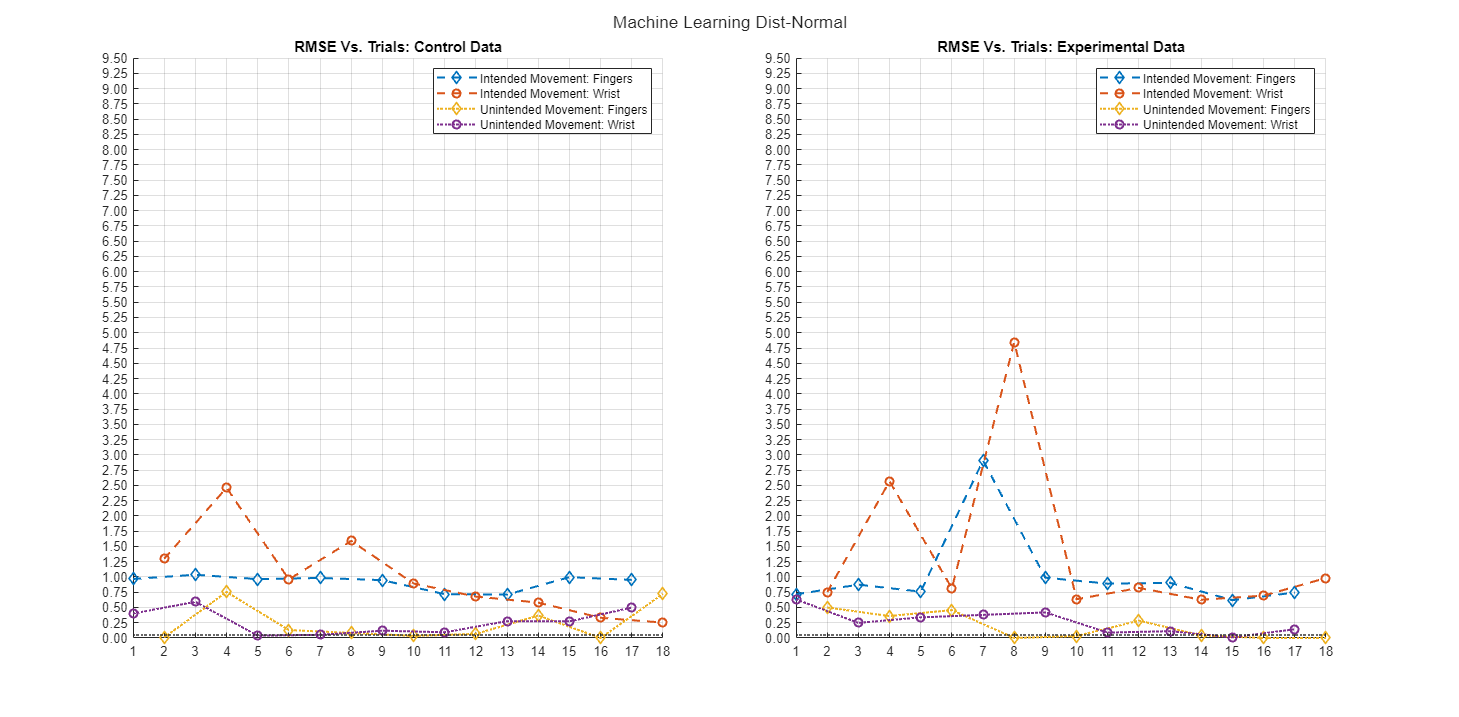


tlo = plot_rmse_norm(control_rmse_knit, experiment_rmse_knit, "Machine Learning Dist-Normal", 2);
ax1 = tlo.Children(2);
ax2 = tlo.Children(4);
ylim(ax1, [0, 9.5])
yticks(ax1, 0:0.25:9.5)
ylim(ax2, [0, 9.5])
yticks(ax2, 0:0.25:9.5)

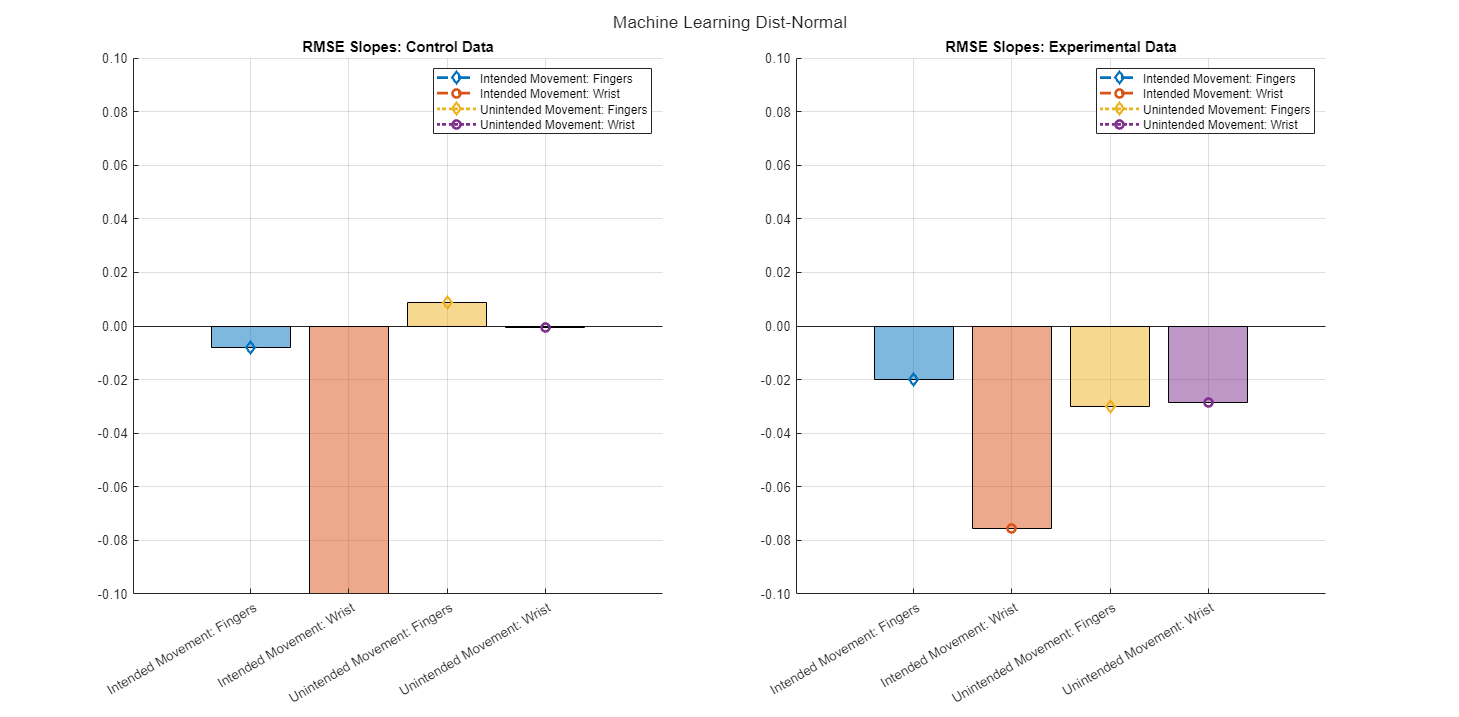

tlo = barplot_rmse_norm(control_rmse_knit, experiment_rmse_knit, "Machine Learning Dist-Normal", 2);

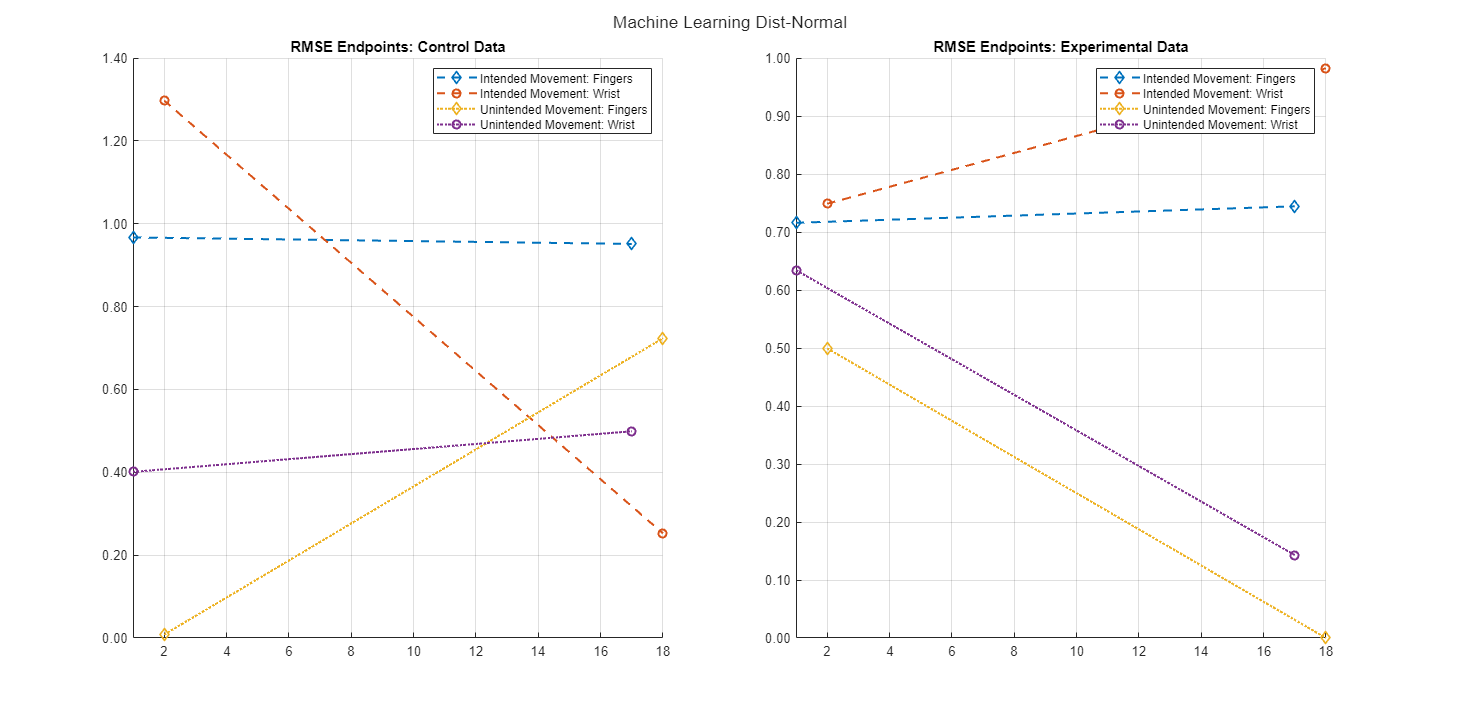

tlo = spaghetti_plot_rmse_norm(control_rmse_knit, experiment_rmse_knit, "Machine Learning Dist-Normal", 2);

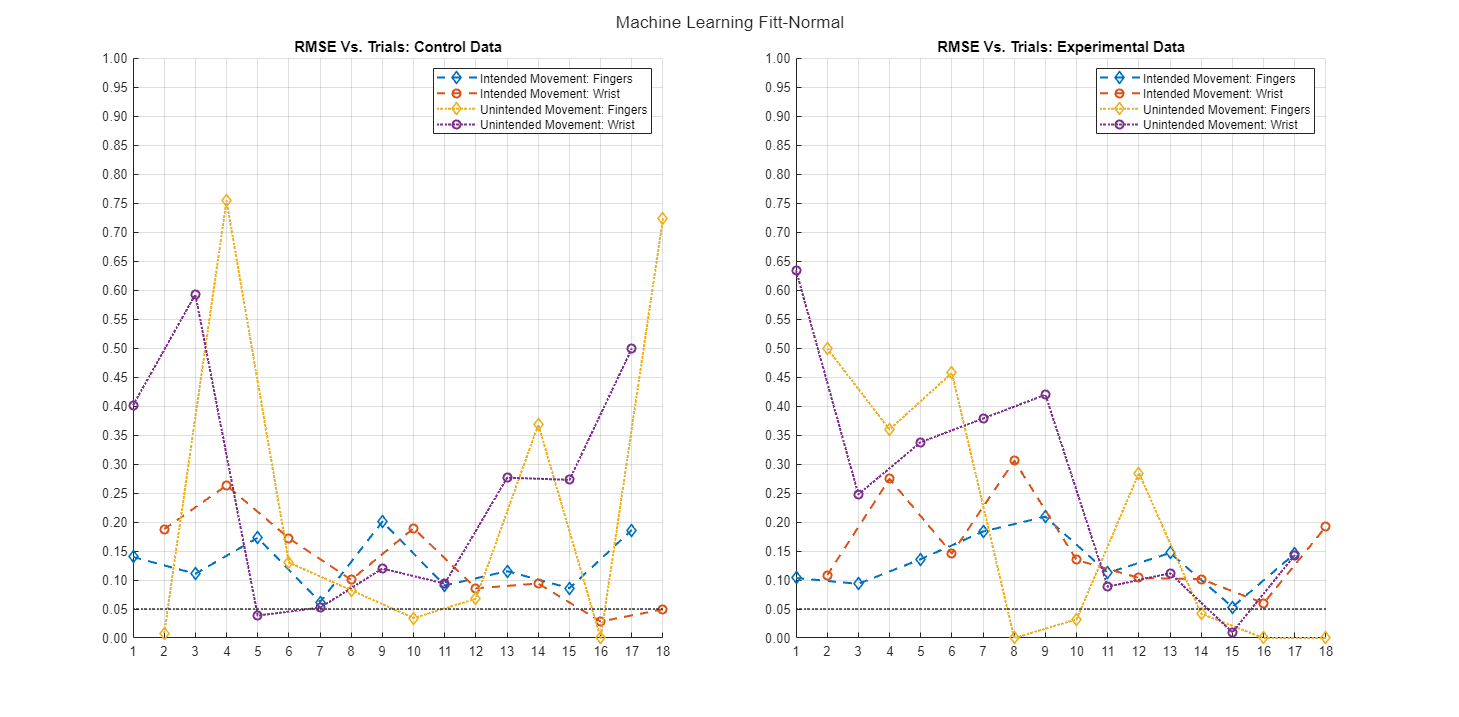


tlo = plot_rmse_norm(control_rmse_knit, experiment_rmse_knit, "Machine Learning Fitt-Normal", 3);

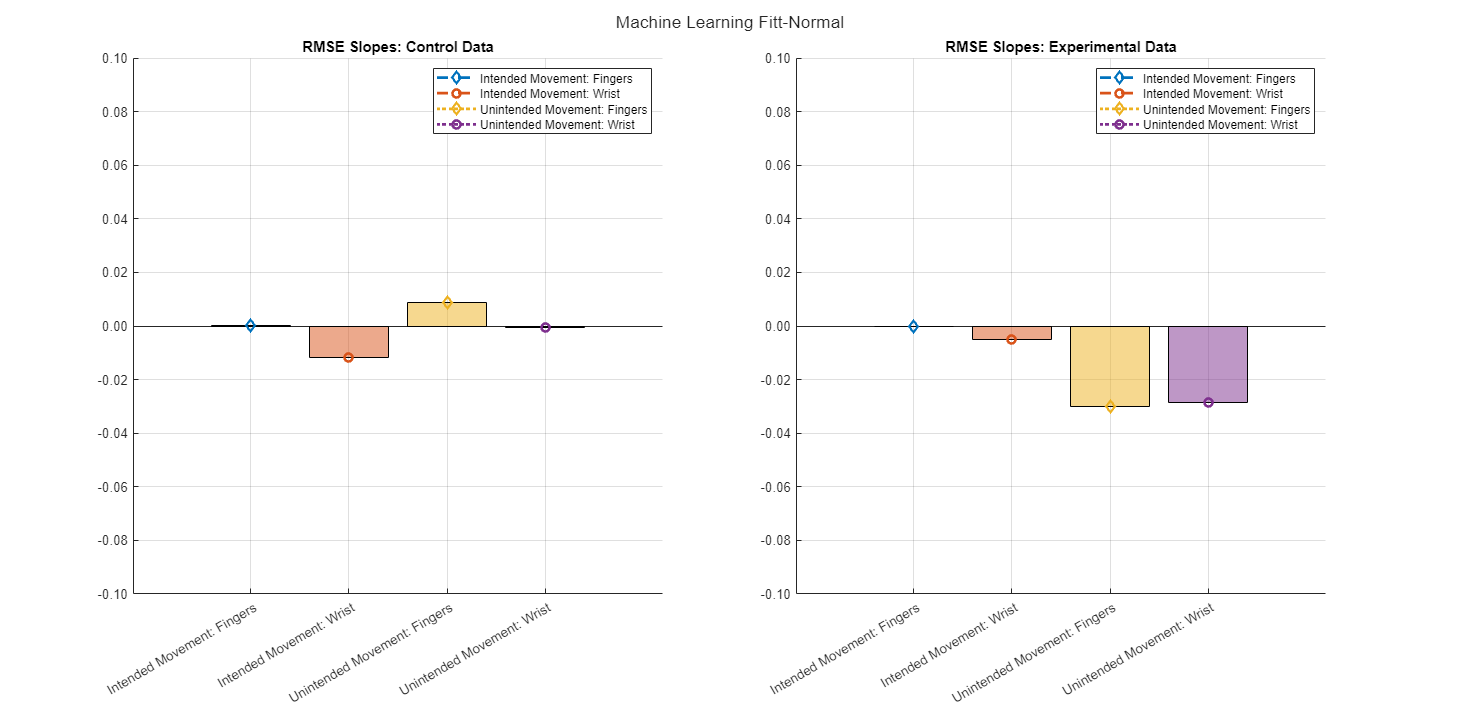

tlo = barplot_rmse_norm(control_rmse_knit, experiment_rmse_knit, "Machine Learning Fitt-Normal", 3);

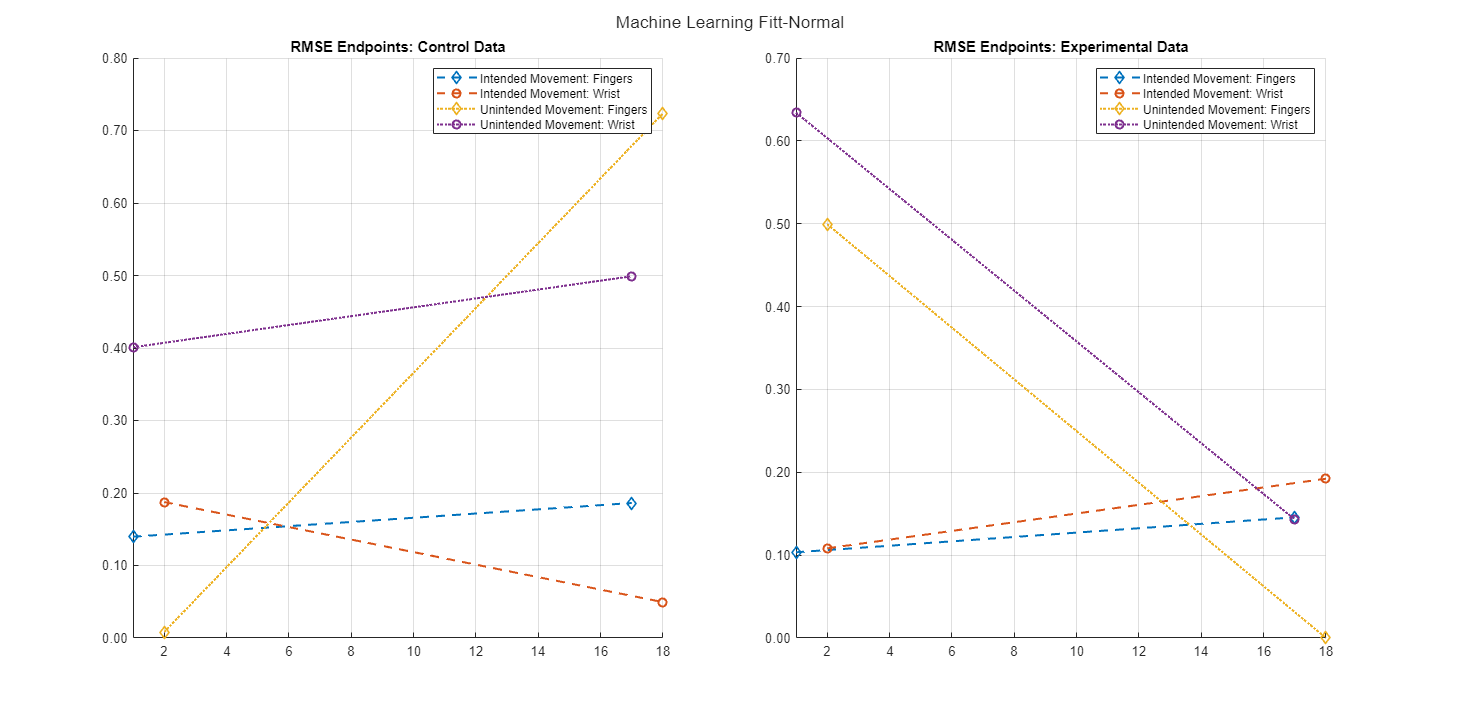

tlo = spaghetti_plot_rmse_norm(control_rmse_knit, experiment_rmse_knit, "Machine Learning Fitt-Normal", 3);

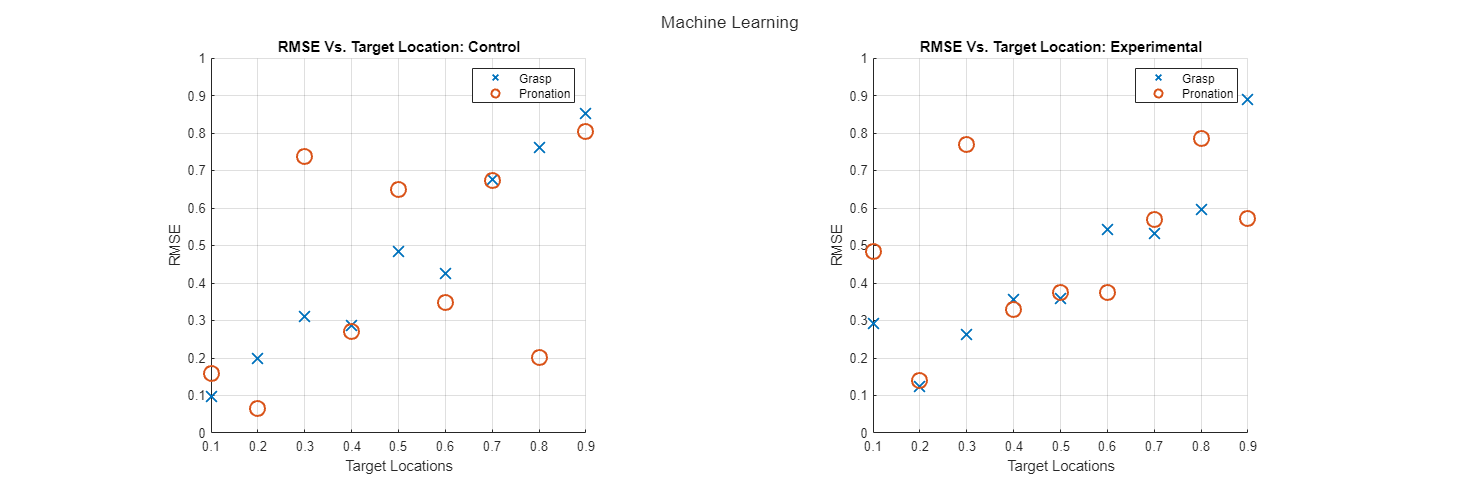

figure('Units','centimeters','Position',[0, 0, 75, 25])
tlo = tiledlayout(1,2);
nexttile
scatter(target_vals(1:2:end), control_rmse_knit(1:2:end,1), 125, 'x', LineWidth=1.5)
hold on
scatter(target_vals(2:2:end), control_rmse_knit(2:2:end,1), 125, 'o', LineWidth=1.5)
hold off
xlim([0.1, 0.9])
xticks([0.1:0.1:0.9])
xlabel('Target Locations')
ylim([0, 1])
ylabel('RMSE')
grid on
title('RMSE Vs. Target Location: Control')
legend('Grasp', 'Pronation')
axis square

nexttile
scatter(target_vals(1:2:end), experiment_rmse_knit(1:2:end,1), 125, 'x', LineWidth=1.5)
hold on
scatter(target_vals(2:2:end), experiment_rmse_knit(2:2:end,1), 125, 'o', LineWidth=1.5)
hold off
xlim([0.1, 0.9])
xticks([0.1:0.1:0.9])
xlabel('Target Locations')
ylim([0, 1])
ylabel('RMSE')
grid on
title('RMSE Vs. Target Location: Experimental')
legend('Grasp', 'Pronation')
axis square

title(tlo, 'Machine Learning')

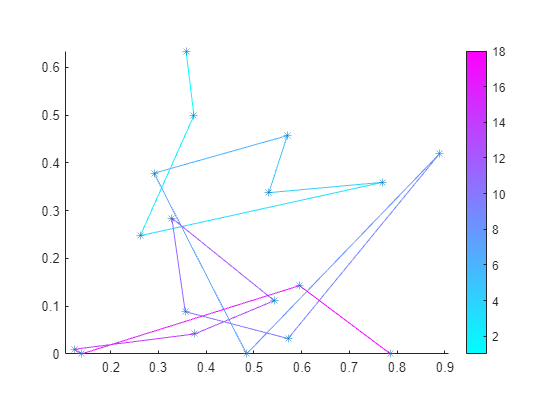

% figure
% plot(RMSE, 'o:')
% xticks([1:20])
% yticks([0:0.05:1])
% ylim([0 1])
% ytickformat('%,0.2f')
% grid on
% box off
% title('RMSE Over Time')
% legend(["Grasp","Pronation"])

figure
% color_vec = 1:length(RMSE_ordered);
% scatter(RMSE_ordered(:,1), RMSE_ordered(:,2), [], color_vec, 'o', 'filled');
% colormap(jet)
% hold on
% plot(RMSE_ordered(:,1), RMSE_ordered(:,2),':')
% hold off
x=experiment_rmse_knit(:,1);
y=experiment_rmse_knit(:,2);
c=1:numel(x);
colormap(cool); % or whatever colormap you want
surface('XData',  [x(:) x(:)],'YData',[y(:) y(:)],...
        'ZData',0*[x(:) x(:)],'CData',[c(:) c(:)],'EdgeColor','flat');
hold on
scatter(x,y,'*')
hold off
axis equal
colorbar

function [rmse_by_int, rmse_by_class] = my_rmse(desired, predicted)
square_error = (desired - predicted).^2;
trial_starts = find(diff(any(desired, 2)) > 0);
trial_stops = find(diff(any(desired, 2)) < 0);
RMSE = -1*ones(length(trial_starts),2);
for i=1:1:length(trial_starts)
    SE_window = square_error(trial_starts(i):trial_stops(i),:);
    RMSE(i,:) = sqrt(sum(SE_window)./length(SE_window));
end

RMSE_ordered = RMSE;
for i=2:2:length(RMSE)
    RMSE_ordered(i,[1 2]) = RMSE_ordered(i,[2 1]);
end
rmse_by_int = RMSE_ordered;
rmse_by_class = RMSE;
end
% trial_stops = find(diff(any(desired, 2)) < 0);
function [RMSE] = my_model_rmse(desired, predicted, stop_idx)
square_error = (desired - predicted).^2;
SE_window = square_error(1:stop_idx,:);
RMSE(1,:) = sqrt(sum(SE_window)./length(SE_window));
end